# Wind Support to Bird migration

**Rapha****ë****l Nussbaumer1****,*********,** **Baptiste Schmid1** **,** **Silke Bauer1** **and Felix Liechti1** 

1 Swiss Ornithological Institute, Sempach, Switzerland 

* Correspondence: raphael.nussbaumer@vogelwarte.ch

Februray 12th, 2021

## Abstract

## Introduction

## Colorscale

Use [Crameri perceptually uniform scientific colormaps](https://www.mathworks.com/matlabcentral/fileexchange/68546-crameri-perceptually-uniform-scientific-colormaps)

if exist('crameri')
    set(0,'DefaultFigureColormap',crameri('batlow'));
else
    set(0,'DefaultFigureColormap',[0.0052,0.0982,0.3498;0.0091,0.1045,0.3509;0.0130,0.1108,0.3520;0.0165,0.1169,0.3531;0.0199,0.1230,0.3541;0.0232,0.1290,0.3552;0.0263,0.1350,0.3562;0.0292,0.1410,0.3572;0.0321,0.1468,0.3582;0.0349,0.1526,0.3592;0.0374,0.1583,0.3602;0.0398,0.1640,0.3612;0.0421,0.1696,0.3622;0.0441,0.1751,0.3631;0.0459,0.1805,0.3640;0.0477,0.1858,0.3649;0.0494,0.1911,0.3658;0.0508,0.1963,0.3667;0.0522,0.2013,0.3675;0.0535,0.2064,0.3684;0.0547,0.2112,0.3692;0.0559,0.2160,0.3700;0.0570,0.2208,0.3707;0.0580,0.2253,0.3715;0.0592,0.2298,0.3723;0.0602,0.2343,0.3730;0.0611,0.2386,0.3737;0.0621,0.2429,0.3744;0.0631,0.2471,0.3750;0.0640,0.2512,0.3757;0.0649,0.2553,0.3764;0.0659,0.2593,0.3770;0.0669,0.2632,0.3776;0.0679,0.2671,0.3782;0.0690,0.2709,0.3788;0.0700,0.2747,0.3793;0.0711,0.2785,0.3799;0.0722,0.2822,0.3804;0.0734,0.2859,0.3810;0.0746,0.2897,0.3815;0.0758,0.2933,0.3819;0.0771,0.2970,0.3824;0.0785,0.3006,0.3828;0.0800,0.3043,0.3832;0.0816,0.3079,0.3836;0.0831,0.3115,0.3839;0.0848,0.3150,0.3842;0.0865,0.3186,0.3845;0.0884,0.3222,0.3847;0.0903,0.3257,0.3849;0.0923,0.3292,0.3850;0.0945,0.3327,0.3851;0.0966,0.3362,0.3851;0.0990,0.3396,0.3851;0.1015,0.3430,0.3850;0.1041,0.3464,0.3848;0.1068,0.3498,0.3845;0.1097,0.3531,0.3842;0.1127,0.3564,0.3838;0.1157,0.3596,0.3833;0.1190,0.3628,0.3827;0.1223,0.3660,0.3820;0.1259,0.3692,0.3813;0.1295,0.3722,0.3804;0.1333,0.3753,0.3794;0.1372,0.3783,0.3783;0.1413,0.3812,0.3771;0.1454,0.3841,0.3758;0.1497,0.3870,0.3744;0.1541,0.3898,0.3729;0.1586,0.3925,0.3713;0.1632,0.3952,0.3696;0.1680,0.3979,0.3678;0.1728,0.4005,0.3659;0.1778,0.4030,0.3638;0.1827,0.4056,0.3617;0.1879,0.4080,0.3595;0.1931,0.4104,0.3572;0.1983,0.4128,0.3548;0.2037,0.4151,0.3523;0.2091,0.4174,0.3497;0.2146,0.4197,0.3470;0.2201,0.4219,0.3443;0.2257,0.4240,0.3415;0.2314,0.4262,0.3386;0.2371,0.4283,0.3356;0.2428,0.4304,0.3326;0.2486,0.4325,0.3296;0.2545,0.4345,0.3264;0.2603,0.4366,0.3233;0.2662,0.4386,0.3201;0.2722,0.4405,0.3168;0.2782,0.4425,0.3136;0.2842,0.4445,0.3102;0.2902,0.4464,0.3069;0.2963,0.4484,0.3035;0.3024,0.4503,0.3001;0.3085,0.4522,0.2967;0.3146,0.4541,0.2933;0.3208,0.4560,0.2898;0.3270,0.4579,0.2864;0.3332,0.4598,0.2829;0.3395,0.4617,0.2795;0.3457,0.4636,0.2760;0.3520,0.4654,0.2725;0.3583,0.4673,0.2690;0.3646,0.4692,0.2655;0.3709,0.4711,0.2621;0.3773,0.4730,0.2586;0.3837,0.4748,0.2551;0.3901,0.4767,0.2517;0.3965,0.4786,0.2482;0.4030,0.4805,0.2447;0.4095,0.4824,0.2413;0.4160,0.4842,0.2379;0.4225,0.4861,0.2345;0.4291,0.4880,0.2311;0.4357,0.4899,0.2277;0.4424,0.4918,0.2244;0.4491,0.4937,0.2211;0.4558,0.4956,0.2178;0.4625,0.4975,0.2145;0.4694,0.4994,0.2113;0.4762,0.5013,0.2081;0.4831,0.5032,0.2050;0.4901,0.5051,0.2020;0.4971,0.5071,0.1990;0.5042,0.5090,0.1961;0.5113,0.5109,0.1933;0.5184,0.5128,0.1906;0.5256,0.5147,0.1880;0.5329,0.5167,0.1855;0.5402,0.5186,0.1831;0.5476,0.5205,0.1809;0.5550,0.5224,0.1789;0.5625,0.5243,0.1770;0.5700,0.5262,0.1753;0.5776,0.5281,0.1738;0.5852,0.5299,0.1725;0.5928,0.5318,0.1714;0.6005,0.5336,0.1706;0.6082,0.5354,0.1701;0.6160,0.5372,0.1698;0.6237,0.5390,0.1698;0.6315,0.5408,0.1701;0.6393,0.5425,0.1706;0.6471,0.5442,0.1715;0.6549,0.5459,0.1726;0.6627,0.5475,0.1740;0.6705,0.5491,0.1757;0.6782,0.5507,0.1778;0.6860,0.5523,0.1801;0.6937,0.5538,0.1826;0.7014,0.5553,0.1855;0.7091,0.5568,0.1885;0.7167,0.5582,0.1919;0.7243,0.5596,0.1954;0.7319,0.5610,0.1992;0.7394,0.5624,0.2032;0.7469,0.5637,0.2074;0.7543,0.5650,0.2118;0.7616,0.5663,0.2163;0.7689,0.5676,0.2210;0.7762,0.5689,0.2259;0.7834,0.5702,0.2310;0.7906,0.5714,0.2362;0.7977,0.5727,0.2415;0.8047,0.5739,0.2470;0.8117,0.5752,0.2526;0.8186,0.5765,0.2583;0.8255,0.5777,0.2642;0.8323,0.5790,0.2702;0.8390,0.5803,0.2764;0.8457,0.5817,0.2826;0.8522,0.5830,0.2890;0.8587,0.5844,0.2956;0.8652,0.5859,0.3023;0.8715,0.5874,0.3091;0.8777,0.5889,0.3161;0.8839,0.5904,0.3232;0.8899,0.5921,0.3305;0.8958,0.5938,0.3379;0.9016,0.5955,0.3454;0.9072,0.5973,0.3531;0.9127,0.5992,0.3610;0.9181,0.6011,0.3690;0.9233,0.6031,0.3771;0.9283,0.6052,0.3854;0.9332,0.6074,0.3938;0.9378,0.6096,0.4023;0.9423,0.6119,0.4110;0.9466,0.6142,0.4198;0.9507,0.6166,0.4286;0.9546,0.6191,0.4376;0.9582,0.6217,0.4466;0.9617,0.6243,0.4557;0.9649,0.6269,0.4649;0.9680,0.6296,0.4741;0.9708,0.6324,0.4833;0.9734,0.6352,0.4925;0.9758,0.6380,0.5018;0.9781,0.6409,0.5111;0.9801,0.6438,0.5203;0.9819,0.6467,0.5296;0.9836,0.6496,0.5388;0.9851,0.6525,0.5480;0.9864,0.6555,0.5571;0.9876,0.6584,0.5662;0.9886,0.6614,0.5753;0.9895,0.6643,0.5842;0.9903,0.6673,0.5932;0.9909,0.6702,0.6020;0.9915,0.6732,0.6108;0.9919,0.6761,0.6196;0.9923,0.6790,0.6283;0.9926,0.6819,0.6369;0.9928,0.6848,0.6454;0.9930,0.6877,0.6539;0.9931,0.6906,0.6624;0.9931,0.6935,0.6708;0.9931,0.6963,0.6792;0.9931,0.6992,0.6875;0.9930,0.7020,0.6958;0.9929,0.7049,0.7041;0.9928,0.7077,0.7124;0.9926,0.7105,0.7206;0.9924,0.7134,0.7289;0.9923,0.7162,0.7371;0.9921,0.7190,0.7454;0.9918,0.7219,0.7537;0.9916,0.7248,0.7620;0.9914,0.7276,0.7703;0.9911,0.7305,0.7786;0.9909,0.7334,0.7870;0.9906,0.7363,0.7954;0.9903,0.7392,0.8038;0.9900,0.7421,0.8123;0.9897,0.7450,0.8208;0.9894,0.7480,0.8294;0.9891,0.7510,0.8380;0.9888,0.7539,0.8466;0.9884,0.7569,0.8553;0.9880,0.7600,0.8641;0.9877,0.7630,0.8729;0.9873,0.7660,0.8817;0.9869,0.7691,0.8906;0.9864,0.7722,0.8995;0.9860,0.7753,0.9084;0.9855,0.7784,0.9174;0.9850,0.7815,0.9265;0.9845,0.7846,0.9355;0.9839,0.7878,0.9446;0.9833,0.7909,0.9537;0.9827,0.7941,0.9629;0.9820,0.7972,0.9721;0.9814,0.8004,0.9813])
end
colorder = [17, 138, 178;82, 43, 41; 204, 164, 59; 67, 100, 54; 228, 87, 46]/255;
set(0,'defaultAxesColorOrder',colorder)

## Data

Load basic data

load('coastlines.mat');% addpath('.function\')

## **Weather radar data**

Bird density, orientation and speed for 37 weather radars in western Europe are downloaded from the ENRAM repository (ERAM, 2020) and processed as explained in Nussbaumer (2021) ([https://doi.org/10.1101/2021.03.08.434434](https://doi.org/10.1101/2021.03.08.434434)). The final dataset consists of bird density (ρ) [bird/km^3], bird flight speed following the east-west component (`u`)  and south-north component (v) [m/s] at 15min resolutions, 200m bin altitude (0-5km) for each radar are available on zenodo ([https://doi.org/10.5281/zenodo.3610184](https://doi.org/10.5281/zenodo.3610184))[.](https://zenodo.org/record/3610185.)

load('../2018/data/dc_corr.mat','dc'); 

**Declare variable used later**

dc_alt = dc(1).alt;
dc_time = dc(1).time;
ndc = numel(dc);
dc_lat = [dc.lat];
dc_lon = [dc.lon];
dc_name = {dc.name};
dc_dem = [dc.heightDEM];

NNT is Normalized night time (-1: sunset to 1 sunrise):

NNT = datenum(repmat(dc_time',1,ndc)-mean(cat(3,[dc.dawn],[dc.dusk]),3)) ./ datenum([dc.dawn]-[dc.dusk])*2;

Day grouping

[G_day,day_num]=findgroups(datenum(dateshift(dc_time,'start','day','nearest')));

We convert the structure data to matrix to ease of use later. At the same time, we do the following (1) convert orientation and speed into vector (NS, EW componenents as complex value), (2) remove data below ground level and most importantly (3) remove all interpolated data because we are not interested in the spatio-temporal consistency of the data, but rather limiting our analysis to the most only original data.

gs=nan(numel(dc_time), numel(dc_alt), ndc); dens=gs; sd_vvp=gs;
for i_d=1:ndc
    % data to keep
    keep = true(size(dc(i_d).dens4));
    keep(repmat(1:dc(i_d).scatter_lim,numel(dc_time),1))=false; % remvove below ground
    keep(isnan(dc(i_d).dens3) | dc(i_d).dens3==0)=false; % remove when not interpolated
    keep(NNT(:,i_d)<-1 & NNT(:,i_d)>1,:) = false;
    
    % density
    tmp = dc(i_d).dens4; tmp(~keep)=nan;
    dens(:,:,i_d) = tmp;
    
    % variance of speed
    tmp = dc(i_d).sd_vvp; tmp(~keep)=nan;
    sd_vvp(:,:,i_d) = tmp;
        
    % groundspeed vector 
    keep(isnan(dc(i_d).u) | isnan(dc(i_d).v))=false; % remove when not interpolated
    tmp = dc(i_d).ub + 1i*dc(i_d).vb; tmp(~keep)=nan;
    gs(:,:,i_d) = tmp;
end

## **Climate Reanalaysis**

The U ([parmID=131](https://apps.ecmwf.int/codes/grib/param-db/?id=131)) and V ([parmID=132](https://apps.ecmwf.int/codes/grib/param-db/?id=132)) component of wind and the air temperature t ([parmID=130](https://apps.ecmwf.int/codes/grib/param-db?id=130)) are downloaed from the ERA5 reanalysis ([https://doi.org/10.24381/cds.bd0915c6](https://doi.org/10.24381/cds.bd0915c6)) at pressure level (from 1000hPa to 550hPa), downloaded at the maximal resoluation (hourly and 0.25°x0.25°). All three variables are linearly interpolated (time-space 4D) at each datapoint of the weather radar data (see [https://rafnuss-postdoc.github.io/BMM/2018/LiveScript/Insect_removal.html#H_38C69C30)](https://rafnuss-postdoc.github.io/BMM/2018/LiveScript/Insect_removal.html#H_38C69C30)) using the [barometric formula](https://en.wikipedia.org/wiki/Barometric_formula)**.**

## Windspeed

ws=nan(numel(dc_time), numel(dc_alt), ndc);
for i_d=1:ndc
    ws(:,:,i_d) = dc(i_d).ws; % windspeed vector 
end

## Air density

Aims is to build a function converting airspeed into energy, to do so, we need the air density on the same data format than the other variable (density, speed etc...)


$$\rho \;=\frac{p}{R_{\textrm{specific}} T}$$


We  assume a constant specific gas constant

R_specific = 287.058; % J/(kg·K)

Pressure is taken from the altitude of each bin with the [barometric formula](https://en.wikipedia.org/wiki/Barometric_formula)**.**

dc_pressure = (1-dc_alt*2.25577*10^(-5)).^(5.25588)*101325/100;

Air density is thus:

airdens=nan(numel(dc_time), numel(dc_alt), ndc);
for i_d=1:ndc
    airdens(:,:,i_d) = repmat(dc_pressure,numel(dc_time),1)*100 ./ dc(i_d).wt /R_specific; % hPa * Pa/hPa / K * kg*K/J = Pa*kg/J = kg/m^3
end

Clear dc not used after

clear dc tmp

## **Airspeed**

Birds' groundspeed ($V_g$) and airspeed ($V_a$) can be computed respectively with


$$V_g =\sqrt{u^2 +v^2 }$$


and

 $V_a =\sqrt{{\left(u-U\right)}^2 +{\left(v-V\right)}^2 }$.

Airspeed vector 

as = gs-ws;

## Wind profit

Assuming a migration orientation of 225° (or 45°), the wind profit, quantify the wind support in the direction of migration (i.e., independant from the bird speed)

v_wp = cosd(45)*real(ws) + sind(45)*imag(ws);

Using the actual ground speed orientation. 

% tmp=ws .* gs./abs(gs);
% v_wpw = real(tmp)+imag(tmp);

Speed norm

% abs(gs) = abs(gs);
% abs(as) = abs(as);
% v_w = abs(ws);

Speed orientation

% angle(gs)

**Plot radar data availability**

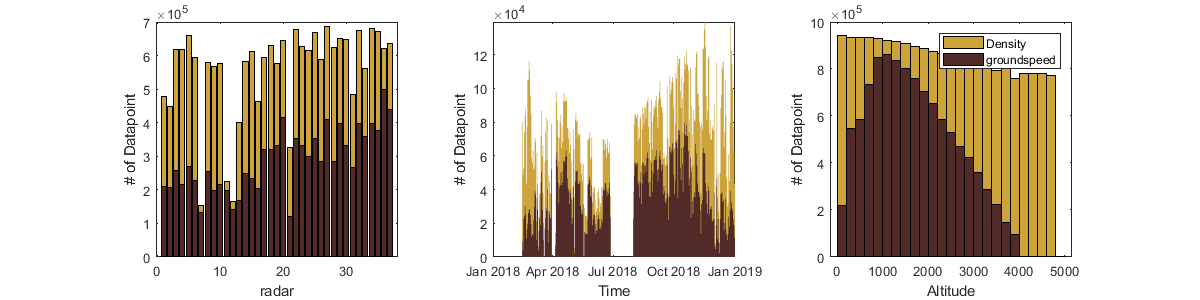

figure('position',[0 0 1200 300]);
subplot(1,3,1); hold on; box on;
bar(reshape(sum(sum(~isnan(dens) & dens~=0,1),2),1,[]),'FaceColor',colorder(3,:))
bar(reshape(sum(sum(~isnan(abs(gs)) & abs(gs)~=0,1),2),1,[]),'FaceColor',colorder(2,:))
xlabel('radar'); ylabel('# of Datapoint')
subplot(1,3,2);  hold on; box on;
bar(datetime(day_num,'convertfrom','datenum'), splitapply(@sum,sum(sum(~isnan(dens) & dens~=0,3),2),G_day'),1,'FaceColor',colorder(3,:));
bar(datetime(day_num,'convertfrom','datenum'), splitapply(@sum,sum(sum(~isnan(abs(gs)) & abs(gs)~=0,3),2),G_day'),1,'FaceColor',colorder(2,:));
axis tight;
xlabel('Time'); ylabel('# of Datapoint')
subplot(1,3,3);  hold on; box on;
bar(dc_alt,sum(sum(~isnan(dens) & dens~=0,1),3),1,'FaceColor',colorder(3,:))
bar(dc_alt,sum(sum(~isnan(abs(gs)) & dens~=0,1),3),1,'FaceColor',colorder(2,:))
xlabel('Altitude'); ylabel('# of Datapoint')
legend('Density','groundspeed')

**Figure  : **Data availability measuring the total number of data point which are not NA or 0 for density and groundspeed (airspeed is same as groundspeed). 

- We have much fewer datapoint of speed than density. Most of them are at high altitude >4000m, where density is weak and speed is unrealiable. 

- Slightly more datapoint for German radar, but nothing important

- Annual coverage is relatively good, matching roughly the density (i.e., speed is only available when many bird are flying). 

## **Method**

We split the dataset in over space and time.

## **Split dataset : Seasonal**

 Over time, we define 4 periods: Early spring (March), Late spring (April), Early autumn (august-september) and late autumn (October). Note that we might want to redefine this period to match bird migration data (e.g., MTR). Here a coarse approach is to use entire month.

id_sp = dc_time>datetime('1-Mar-2018') & dc_time<datetime('1-May-2018');
id_esp = dc_time>datetime('1-Mar-2018') & dc_time<datetime('1-April-2018');
id_lsp = dc_time>datetime('1-April-2018') & dc_time<datetime('1-May-2018');
id_au = dc_time>datetime('1-August-2018') & dc_time<datetime('1-Nov-2018');
id_eau = dc_time>datetime('1-August-2018') & dc_time<datetime('1-Oct-2018');
id_lau = dc_time>datetime('1-Oct-2018') & dc_time<datetime('1-Nov-2018');

All periods combined

id_s = [id_esp; id_lsp; id_eau; id_lau];
id_s_name = {'March','April','Aug-sept.','October'};
id_s_col = [38, 70, 83;42, 157, 143;233, 196, 106;244, 162, 97];
id_sp_col = [51 137 86]/255;
id_au_col = [229 103 7]/255;

We might also want to compare data of 2016 to see the difference.

id_2016 = dc_time>datetime('19-Sep-2018') & dc_time<datetime('9-Oct-2018');

## Split dataset: Geographic

We group radars in two groups of equal size based on their position along the general flow of migration (south-west / north east gradient with a flow orientation of `222°`). The Southern group include all French radar (18) exepect `frman` and the northern group include all germans (16), dutch (2) and Belgium (1) radars.

id_no = [true(16,1); false(12,1); true ;false(6,1) ;true(2,1)];
id_so = ~id_no;
id_de = [false; true(15,1); false(21,1)];
id_fr = [false(16,1); true(19,1); false(2,1)];
id_sno_col = [82 88 166; 178 164 34]/255;

Illustration

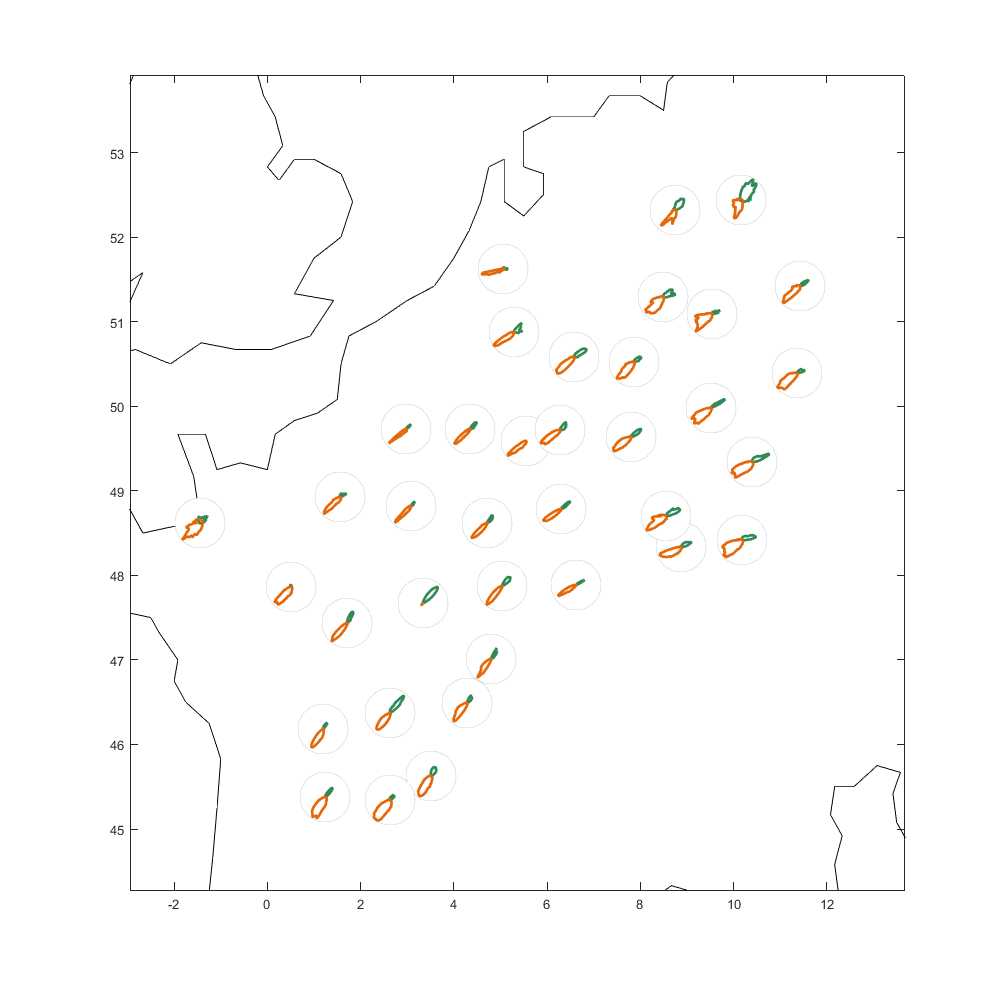

w=.07; h=0.05; m =.2; 
pw = @(lon) (lon-min(dc_lon))/(max(dc_lon)-min(dc_lon))*(1-2*m)+m;
ph = @(lat) (lat-min(dc_lat))/(max(dc_lat)-min(dc_lat))*(1-2*m)+m;

figure('position',[0 0 1000 1000]);
plot(coastlon,coastlat,'-k');
xlim([min(dc_lon) max(dc_lon)])
ylim([min(dc_lat) max(dc_lat)])

for i_d=1:ndc
    [esp,hsp,Mdd(i_d,1)] = histVdens(gs(id_sp,:,i_d), dens(id_sp,:,i_d), 100);
    [eau,hau,Mdd(i_d,2)] = histVdens(gs(id_au,:,i_d), dens(id_au,:,i_d), 100);
    %[e2016,h2016,~,~,Mdd(i_d,3)] = histvdens(dc(i_d).dd(id_2016,:), dens(id_2016,:,i_d).*abs(gs(id_2016,:,i_d)), 100);
    
    subAX = axes('position',[pw(dc_lon(i_d))-w/2 ph(dc_lat(i_d))-h/2 w h]);
    %polarplot(deg2rad(e2016),h2016);hold on
    polarplot(esp,hsp,'Color',id_sp_col,'linewidth',2);hold on
    polarplot(eau,hau,'Color',id_au_col,'linewidth',2);
    %tmp=round(reshape(dens(id_sp,:,i_d).*abs(gs)(id_sp,:,i_d),1,[])); tmp(isnan(tmp)) = 0;
    %polarhistogram(repelem(deg2rad(reshape(dc(i_d).dd(id_sp,:),1,[])), tmp),38); hold on;
    %polarplot(angle([Mdd(i_d,1) Mdd(i_d,1)]),[0 max(hsp)],'--','Color',id_sp_col,'LineWidth',2)
    %polarplot(angle([Mdd(i_d,2) Mdd(i_d,2)]),[0 max(hau)],'--','Color',id_au_col,'LineWidth',2)
    % polarplot(angle([Mdd(i_d,3) Mdd(i_d,3)]),[0 max([h2016;h2016])],'LineWidth',2)
    Ax = gca; Ax.ThetaGrid = 'off'; Ax.RGrid='off'; Ax.RTickLabel = []; Ax.ThetaTickLabel = [];
    %title(dc_name(i_d),'Color',id_sno_col(id_no(i_d)+1,:))
end

**Figure : **Distribution of bird flight direction (groundspeed) weighted by the MTR (density x speed) for Spring (blue) and Autumn (red). Radars are grouped in the the northern (yellow) and southern (blue). *Location not correct yet...*

Average bird flight direction per radar

nanmean(rad2deg(angle(Mdd)))

ans =   -43.9761  134.3720


## Energy Calculation

In this section we define the energy power function, which provides the energy `eng` spent by a bird of mass `m`, wingspan `B` would spend flying at `vt` and with air density `airdens`. We also explore quickly the variation of optimal speed (i.e, lower energy) for different type of bird. 

Parameter for energy speding

k=1.2; % [-] Induced power factor (p. 45).
% m [kg] mass of bird.
gcst = 9.81; % [ms-2] gravity constant
% Vt [m/s] true speed (bird speed-wind speed)
% B [m] Wing span. 
% airdens = 1; % Air density 
Sb = @(m) 0.00813*m^0.666; % [m2] body frontal area
CDb = 0.1; % [-] body drag coefficient (p. 51).
Cpro = 8.4;
Ra = 7;

Define the function of energy

f_eng = @(Vt, airdens, m, B) (2*k*(m*gcst)^2)./(Vt*pi*B.^2.*airdens) + airdens.*Vt.^3*Sb(m)*CDb/2 + Cpro/Ra*1.05*k^(3/4)*m^(3/2)*gcst^(3/2)*Sb(m)^(1/4)*CDb^(1/4)./airdens.^(1/2)/B^(3/2);

Use data from appendix of Aurbach et al., (2020) for average mass and wingspan for migrant. 

Sp = table();
Sp.name = {'Willow Warbler'	'Tree Pipit'	'Common Chiffchaff'	'Spotted Flycatcher'	'Garden Warbler'	'Common Whitethroat'	'European Pied Flycatcher'	'Common Redstart'	'Wood Warbler'	'Eurasian Blackcap' 'Song Thrush'}';
Sp.massmin = [8 	20	6	13	16	12	9	12	7	14 83]';
Sp.massmax = [10	25	9	19	23	18	15	20	12	20 83]';
Sp.wingmin = [17	25	15	23	20	19	22	21	20	22 34]';
Sp.wingmax = [22	27	21	25	24	23	24	24	24	24 34]';
Sp.abondance = [27.5	12.7	11.3	8.7	7.3	7.1	6.8	6.6	6.1	5.9 nan]';

Compute average mass and wingspan

Sp.massmean = (Sp.massmin+Sp.massmax)/2/1000; % [kg]
Sp.wingmean = (Sp.wingmin+Sp.wingmax)/2/100; % [m]

Sort the table by mass

Sp=sortrows(Sp,'massmean')

Sp = 11×8 table
                name                massmin    massmax    wingmin    wingmax    abondance    massmean    wingmean
    ____________________________    _______    _______    _______    _______    _________    ________    ________

    {'Common Chiffchaff'       }       6          9         15         21         11.3        0.0075       0.18  
    {'Willow Warbler'          }       8         10         17         22         27.5         0.009      0.195  
    {'Wood Warbler'            }       7         12         20         24          6.1        0.0095       0.22  
    {'European Pied Flycatcher'}       9         15         22         24          6.8         0.012       0.23  
    {'Common Whitethroat'  

Compute the weighted average (accounting for abundance of each species

B_avg = nansum(Sp.wingmean.*Sp.abondance/100);
m_avg = nansum(Sp.massmean.*Sp.abondance/100);

Filter specie of interest

Sp=Sp([2 10 11],:);

**Energy as a function of species mass and wingspan**

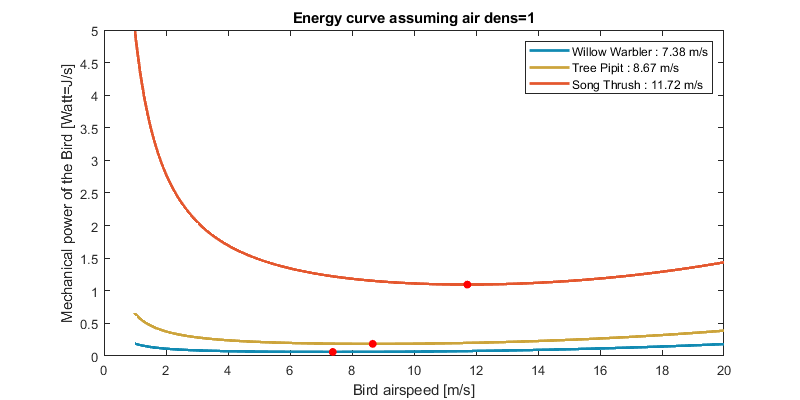

vt=1:0.01:20; 
p=nan(size(Sp,1),1);
figure('position',[0 0 800 400]); hold on; box on;
for i=1:size(Sp,1)
    Pvt = f_eng(vt, 1, Sp.massmean(i), Sp.wingmean(i));
    [~, tmp] = min(Pvt); 
    p(i)=plot(vt, Pvt,'LineWidth',2,'displayname',[Sp.name{i} ' : ' num2str(vt(tmp)) ,' m/s' ]);
    scatter(vt(tmp),min(Pvt),'or','filled')
end
legend(p); xlabel('Bird airspeed [m/s]'); ylabel('Mechanical power of the Bird [Watt=J/s]');
title('Energy curve assuming air dens=1')

The variation of optimal speed does not seem huge with these bird (7.2 - 8.4 m/s). But, we are  missing some bigger bird (e.g., thrush).

**Energy as a function of air density**

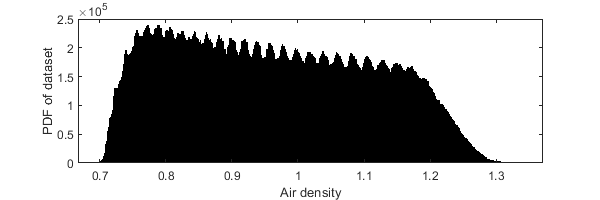

figure('position',[0 0 600 200]); histogram(airdens); xlabel('Air density'); ylabel('PDF of dataset')

Air density presents in the database.

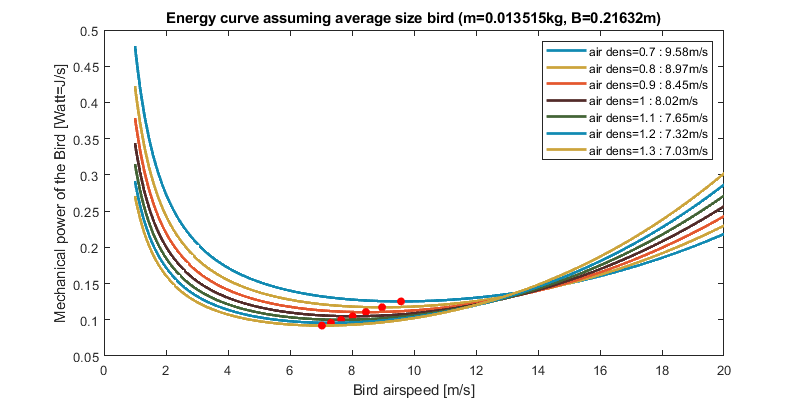

figure('position',[0 0 800 400]); hold on; box on;
ad = 0.7:0.1:1.3;
p=nan(size(ad));
for i = 1:numel(ad)
    Pvt = f_eng(vt,ad(i),m_avg,B_avg);
    [~, tmp] = min(Pvt); 
    p(i)=plot(vt, Pvt,'LineWidth',2,'displayname',['air dens=' num2str(ad(i)) ' : ' num2str(vt(tmp)) 'm/s']);
    scatter(vt(tmp),min(Pvt),'or','filled')
end
legend(p); xlabel('Bird airspeed [m/s]'); ylabel('Mechanical power of the Bird [Watt=J/s]');
title(['Energy curve assuming average size bird (m=' num2str(m_avg) 'kg, B=' num2str(B_avg) 'm)'])

Note that air density plays also a role in the optimale speed of bird, whithin the variation of the airdensity observed (computed from ERA dataset). 

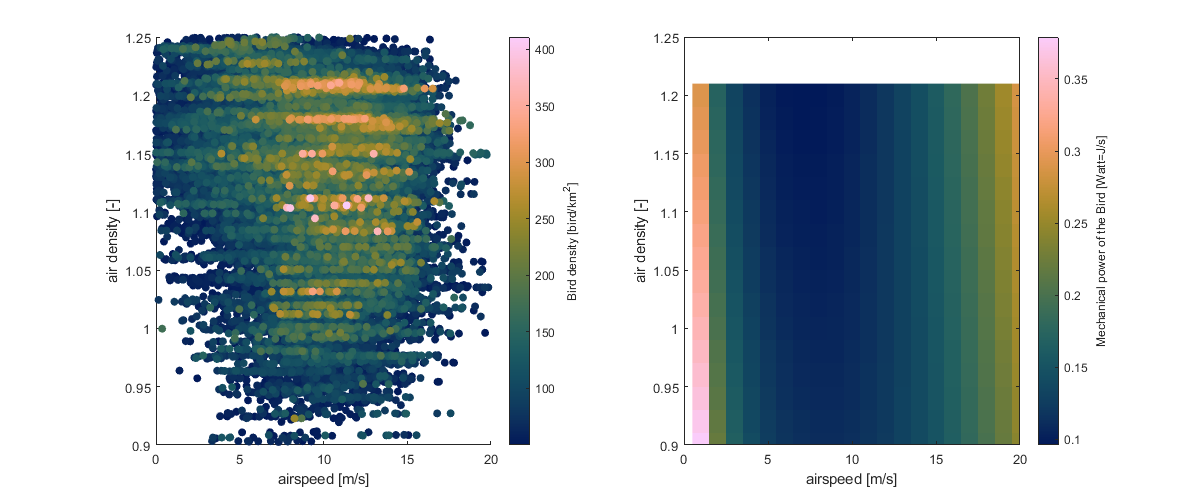

[V,A] = meshgrid(1:20,0.9:0.02:1.2);
E = f_eng(V, A, m_avg,B_avg);
lim = 50;
tmp = [abs(as(dens>lim)) airdens(dens>lim) dens(dens>lim)];
[~,idx] = sort(tmp(:,3)); % sort just the first column
tmp = tmp(idx,:);
figure('position',[0 0 1200 500]); 
subplot(1,2,1)
scatter(tmp(:,1),tmp(:,2),[],tmp(:,3),'filled')
xlabel('airspeed [m/s]'); ylabel('air density [-]'); 
c=colorbar; c.Label.String='Bird density [bird/km^2]'; 
xlim([0 20]); ylim([0.9 1.25]);
subplot(1,2,2);
imagesc(V(1,:),A(:,1),E); 
ax = gca; ax.YDir = 'normal';
xlim([0 20]); ylim([0.9 1.25]);
xlabel('airspeed [m/s]'); ylabel('air density [-]'); 
c=colorbar; c.Label.String='Mechanical power of the Bird [Watt=J/s]'; 

In this figure, I compare the airspeed/airdensity usage of bird with the optimal according to mechanical theory. Left subplot shows the actually usage (warmer color=more bird), and right panel shows the optimal for an average sized bird (colder cooler=more optimal). 

- Air density does not playa big role

- Bird should really not fly lower than 3m/s, yet we do observed some airspeed very low. 

- Generally, highest density are present with airspeed slightly higher than theory (9-12m/s vs 7-10 m/s).

Compute the energy for the entire dataset assuming an averaged size bird.

eng = f_eng(abs(as), airdens, m_avg, B_avg);

## Reshape data as table

Reshape into table to reduce space and help in the analysis

[tmp_time, tmp_alt, tmp_radar] = meshgrid(dc_time,dc_alt,1:37);
T = table(dens(:),abs(gs(:)),angle(gs(:)),abs(as(:)),angle(as(:)),abs(ws(:)),angle(ws(:)),tmp_time(:),tmp_alt(:),tmp_radar(:),'VariableNames',{'dens','grounspeed','grounddir','airspeed','airdir','windspeed','windir','time','alt','radar'});
T

## Anaylsis and Results

## Air vs Ground Overall

First, I'm looking at confirming basic trend which are already known to check that all the methodolgy and dataset are correct. 

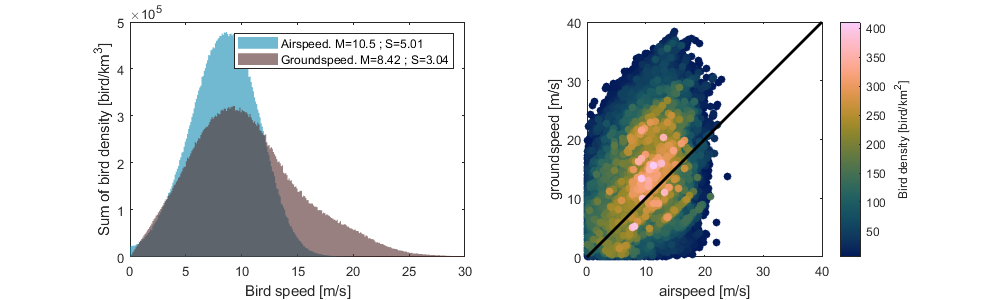

figure('position',[0 0 1000 300]);
subplot(1,2,1); hold on;
[b,h,Ma,Sa] = histvdens(abs(as), dens);
bar(b,h,1,'FaceAlpha',0.6);
[b,h,Mg,Sg] = histvdens(abs(gs), dens);
bar(b,h,1,'FaceAlpha',0.6);

%plot(0:30,normpdf(0:30,Mg,Sg)./max(normpdf(0:30,Mg,Sg))*max(tmp3),'-r');
%plot(0:30,normpdf(0:30,M,Sa)./max(normpdf(0:30,M,Sa))*max(tmp3),'-r');
legend(['Airspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Groundspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
xlabel('Bird speed [m/s]'); box on
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(1,2,2); hold on;
[~, id] = sort(dens(:)); id2 = id(dens(id)>5); % only keep density >5bird/km^2 for computing reason
scatter(abs(as(id2)),abs(gs(id2)),[],dens(id2),'filled'); axis tight equal;
plot([0 40],[0 40],'k','LineWidth',2); box on
xlabel('airspeed [m/s]'); ylabel('groundspeed [m/s]');
c=colorbar; c.Label.String='Bird density [bird/km^2]';

Histograms of airspeed and ground speed are normalized by the density of bird, that is, each bin of bird speed is multiply not by the number of occuruance in the dataset but by the sum of all bird density flying at this speed. 

(a) Bird move (i.e. groundspeed) at around 10.5 m/s (sd=5) while their air speed is actually smaller and more restricted to a speed of 8.4m/s (sd:3).

(b) There are more birds in the air (high bird density) when their ground speed is higher than their airspeed, in other term when the wind is supporting their movement. 

## Air vs Ground **during the season**

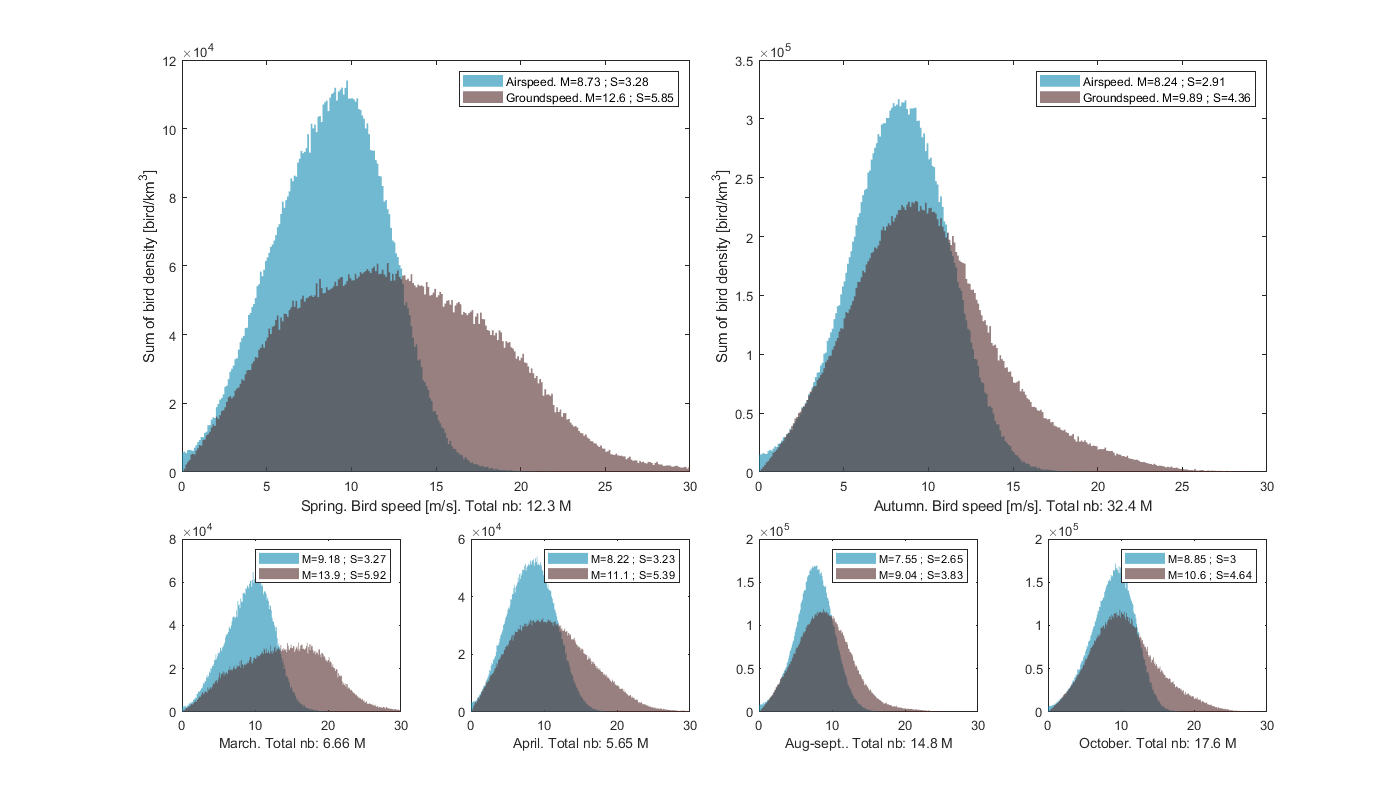

figure('position',[0 0 1400 800]);

subplot(3,4,[1 6]); hold on;
[b,h,Ma,Sa] = histvdens(abs(as(id_sp,:,:)),dens(id_sp,:,:));
bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[b,h,Mg,Sg] = histvdens(abs(gs(id_sp,:,:)),dens(id_sp,:,:));
bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
ylabel('Sum of bird density [bird/km^3]');
%yyaxis right; 
% [b,h,Mw,Sw] = histvdens(v_w(id_sp,:,:),dens(id_sp,:,:));
% bar(b,h./sum(h),1,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
% [b,h,Mw,Sw] = histvdens(v_wp(id_sp,:,:),dens(id_sp,:,:));
% bar(b,h./sum(h),1,'FaceAlpha',0.6, 'DisplayName', ['Windprofit 45°. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
% [b,h,Mw,Sw] = histvdens(v_wpw(id_sp,:,:),dens(id_sp,:,:));
% bar(b,h./sum(h),1,'FaceAlpha',0.6, 'DisplayName', ['Windprofit groundspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
xlabel(['Spring. Bird speed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,:))))/1000000,3) ' M']);
xlim([0 30]); box on; legend; 

subplot(3,4,[3 8]); hold on;
[b,h,Ma,Sa] = histvdens(abs(as(id_au,:,:)),dens(id_au,:,:));
bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[b,h,Mg,Sg] = histvdens(abs(gs(id_au,:,:)),dens(id_au,:,:));
bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
ylabel('Sum of bird density [bird/km^3]');
% yyaxis right; 
%[b,h,Mw,Sw] = histvdens(v_w(id_au,:,:),dens(id_au,:,:));
% bar(b,h./sum(h),1,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
% [b,h,Mw,Sw] = histvdens(v_wp(id_au,:,:),dens(id_au,:,:));
% bar(b,h./sum(h),1,'FaceAlpha',0.6, 'DisplayName', ['Windprofit 45°. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
% [b,h,Mw,Sw] = histvdens(v_wpw(id_au,:,:),dens(id_au,:,:));
% bar(b,h./sum(h),1,'FaceAlpha',0.6, 'DisplayName', ['Windprofit groundspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
xlabel(['Autumn. Bird speed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,:))))/1000000,3) ' M']);
xlim([0 30]); box on; legend; 
for i_s=1:size(id_s,1)
    subplot(3,4,8+i_s); hold on
    [b,h,Ma,Sa] = histvdens(abs(as(id_s(i_s,:),:,:)),dens(id_s(i_s,:),:,:));
    bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
    [b,h,Mg,Sg] = histvdens(abs(gs(id_s(i_s,:),:,:)),dens(id_s(i_s,:),:,:));
    bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
%    [b,h,Mw,Sw] = histvdens(v_w(id_s(i_s,:),:,:),dens(id_s(i_s,:),:,:));
%     yyaxis right; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
%     [b,h,Mw,Sw] = histvdens(v_wp(id_s(i_s,:),:,:),dens(id_s(i_s,:),:,:));
%     bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Windprofit 45°. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
    legend; xlabel([id_s_name{i_s} '. Total nb: ' num2str(nansum(nansum(nansum(dens(id_s(i_s,:),:,:))))/1000000,3) ' M']);xlim([0 30]);
    box on;
end

While the bird are moving with quite different ground speed (blue) regime in Spring (left) and Autumn (right), their actual airspeed (red) is impresively similar. Note that the total number of bird measured is very different in spring (8M bird/km3) and autumn (17M bird/km3). This is because spring is shorter, thus less measurement and it doesn't represent the actual number of bird flying through. 

Compute the daily ground speed, airspeed and windspeed. 

id=~(isnan(abs(as))|isnan(abs(ws)));
        
tmp = repmat(G_day',1,size(dens,2),size(dens,3));
[G,Gid]=findgroups(tmp(id));

densd = nan(numel(unique(G_day)),1);
mt=nan(numel(unique(G_day)),5);
densd(Gid) = splitapply(@nansum,dens(id),G);
mt(Gid,1) = splitapply(@nansum,abs(as(id)).*dens(id),G) ./ densd(Gid);
mt(Gid,2) = splitapply(@nansum,abs(gs(id)).*dens(id),G) ./ densd(Gid);
mt(Gid,3) = splitapply(@nansum,abs(ws(id)).*dens(id),G) ./ densd(Gid);
mt(Gid,4) = splitapply(@nansum,v_wp(id).*dens(id),G) ./ densd(Gid);
%mt(Gid,5) = splitapply(@nansum,v_wpw(id).*dens(id),G) ./ densd(Gid);

% st = splitapply(@(x) nanvar(x(:,1),x(:,2)),[X(:) W(:)],G(:));

Moving average

mtm = movmean(mt.*densd,7,'omitnan') ./ movmean(densd,7,'omitnan');

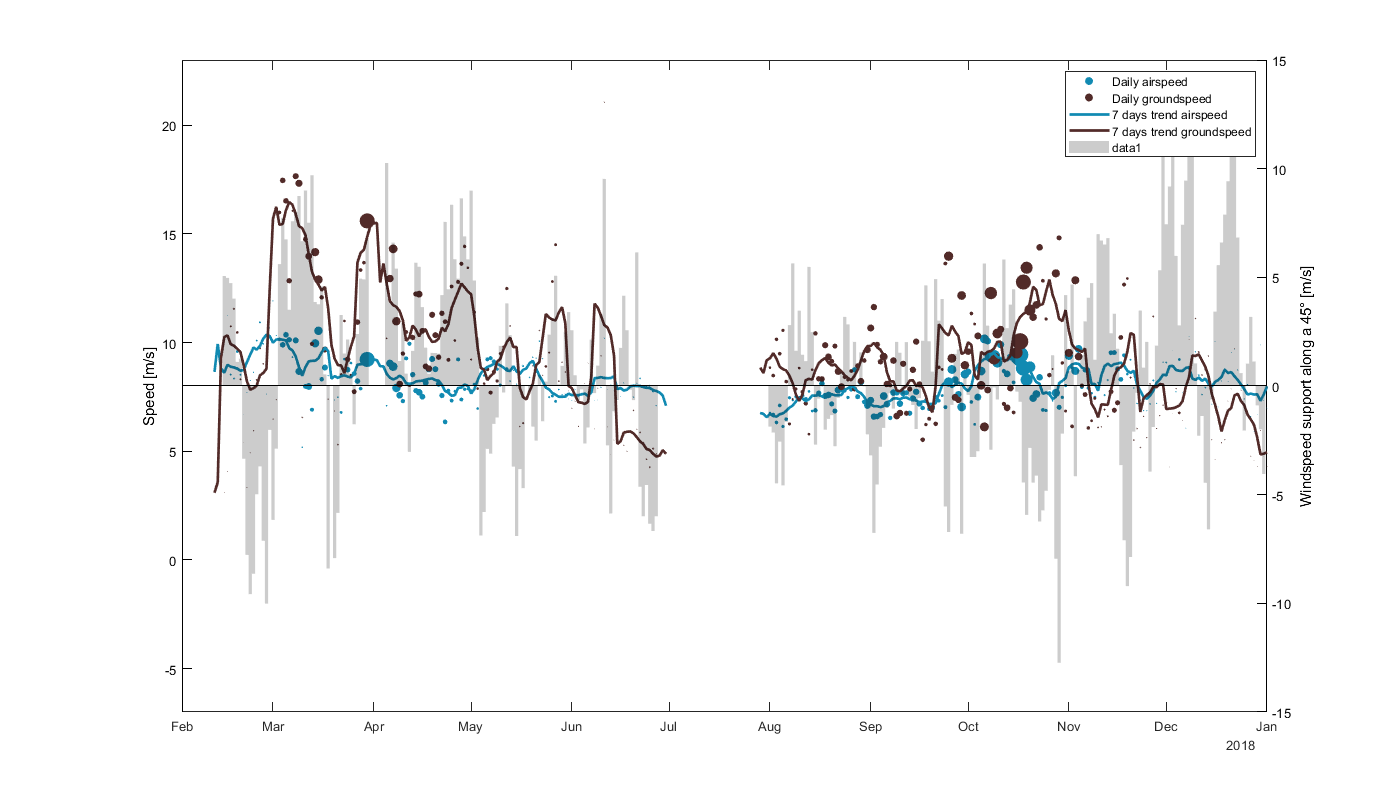

t = datetime(day_num,'convertfrom','datenum');
figure('position',[0 0 1400 800]); 
%subplot(3,1,[1 2]);
hold on;
scatter(t,mt(:,1),densd/10000,'filled')
scatter(t,mt(:,2),densd/10000,'filled')
set(gca, 'ColorOrder', circshift(get(gca, 'ColorOrder'), 2))
plot(t,mtm(:,1:2),'linewidth',2)
% scatter(t,mt(:,3),densd/10000,'filled')
tmp = get(gca,'xlim'); box on; axis tight; ylim(8+[-15 15]); 
legend('Daily airspeed','Daily groundspeed','7 days trend airspeed','7 days trend groundspeed');
ylabel('Speed [m/s]')
yyaxis right;
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
% subplot(3,1,3); 
bar(t,mt(:,4),1,'k','FaceAlpha',0.2); xlim(tmp); box on; ylim([-15 15]); 
ylabel('Windspeed support along a 45° [m/s]')

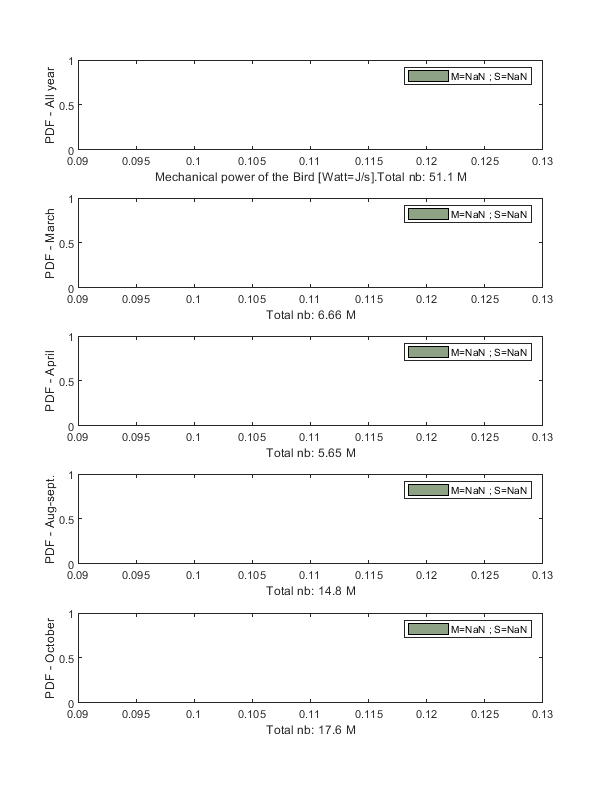

figure('position',[0 0 600 800]);
subplot(5,1,1);
[b,h,Mg,Sg] = histvdens(eng, dens, 0.09:0.001:0.15);
bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)],'FaceColor',colorder(4,:));xlim([0.09 0.13])
legend; xlabel(['Mechanical power of the Bird [Watt=J/s].Total nb: ' num2str(nansum(nansum(nansum(dens)))/1000000,3) ' M']); 
box on; ylabel('PDF - All year')
for i_s=1:size(id_s,1)
    subplot(5,1,i_s+1);
    [b,h,Mg,Sg] = histvdens(eng(id_s(i_s,:),:,:), dens(id_s(i_s,:),:,:),0.09:0.001:0.15);
    bar(b,h,1,'FaceAlpha',0.6, 'DisplayName',['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)],'FaceColor',colorder(4,:));xlim([0.09 0.13])
    legend; xlabel(['Total nb: ' num2str(nansum(nansum(nansum(dens(id_s(i_s,:),:,:))))/1000000,3) ' M']); 
    box on; ylabel(['PDF - ' id_s_name{i_s}])
end

Distribution of the energy spend by bird for various period of the year. We account for the density of bird (i.e., how many bird are spending this energy). But we do not account for change of mass. 

This figure reproduces Figure .. of Horton et al. 2016 ([https://doi.org/10.1642/AUK-16-105.1](https://doi.org/10.1642/AUK-16-105.1)).

The difference of processing includes:

- 3 autumn season, 2 spring season (2013-2015). March 1 to June 15.August 1 to November 15

- Same: civil twilight, discard when precipication 

- eliminate when VAD RMSE is >5 (poor fit) and <1 (insects).

- keep up to 2km altitude.

- "For purposes of averaging we weighted all measures following the distribution of the vertical profile of reflectivity (dBZ)". Not sure what this means. Weighted by reflecitivtiy or reflectivty normalized over verctical profile?

- airspeeds less than 5 m/s

- Weight wind direction by reflecitivity x windspeed

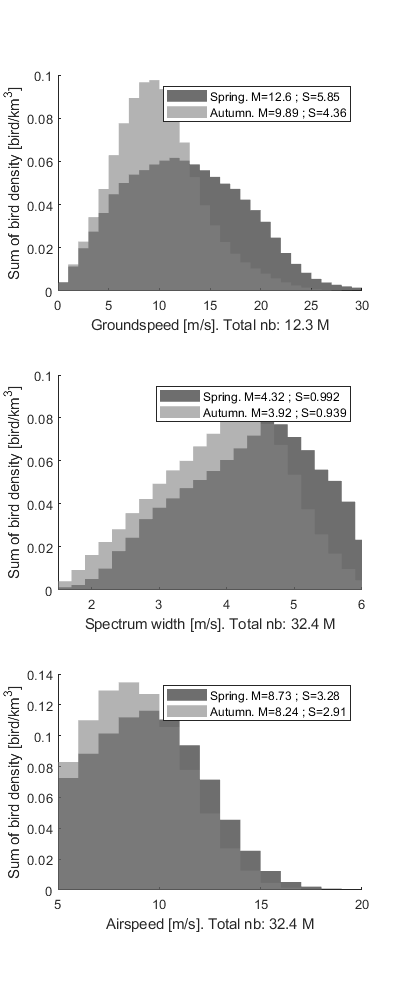

figure('position',[0 0 400 1000]);

subplot(3,1,1); hold on;
[b,h,Mg,Sg] = histvdens(abs(gs(id_sp,:,:)),dens(id_sp,:,:),0:1:30);
bar(b,h/sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Spring. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)],'FaceColor',[.05 .05 .05],'EdgeAlpha',0);
[b,h,Mg,Sg] = histvdens(abs(gs(id_au,:,:)),dens(id_au,:,:),0:1:30);
bar(b,h./sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Autumn. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)],'FaceColor',[.5 .5 .5],'EdgeAlpha',0);
legend; xlabel(['Groundspeed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,:))))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([0 30]);

subplot(3,1,2); hold on;
[b,h,Ma,Sa] = histvdens(sd_vvp(id_sp,:,:),dens(id_sp,:,:),1.5:0.2:10);
bar(b,h/sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Spring. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.05 .05 .05],'EdgeAlpha',0);
[b,h,Ma,Sa] = histvdens(sd_vvp(id_au,:,:),dens(id_au,:,:),1.5:0.2:10);
bar(b,h/sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Autumn. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.5 .5 .5],'EdgeAlpha',0);
legend; xlabel(['Spectrum width [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,:))))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([1.5 6]);

subplot(3,1,3); hold on;
[b,h,Ma,Sa] = histvdens(abs(as(id_sp,:,:)),dens(id_sp,:,:),0:1:20);
bar(b,h/sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Spring. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.05 .05 .05],'EdgeAlpha',0);
[b,h,Ma,Sa] = histvdens(abs(as(id_au,:,:)),dens(id_au,:,:),0:1:20);
bar(b,h/sum(h),1,'FaceAlpha',0.6, 'DisplayName',['Autumn. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)],'FaceColor',[.5 .5 .5],'EdgeAlpha',0);
legend; xlabel(['Airspeed [m/s]. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,:))))/1000000,3) ' M']);
ylabel('Sum of bird density [bird/km^3]'); xlim([5 20]);

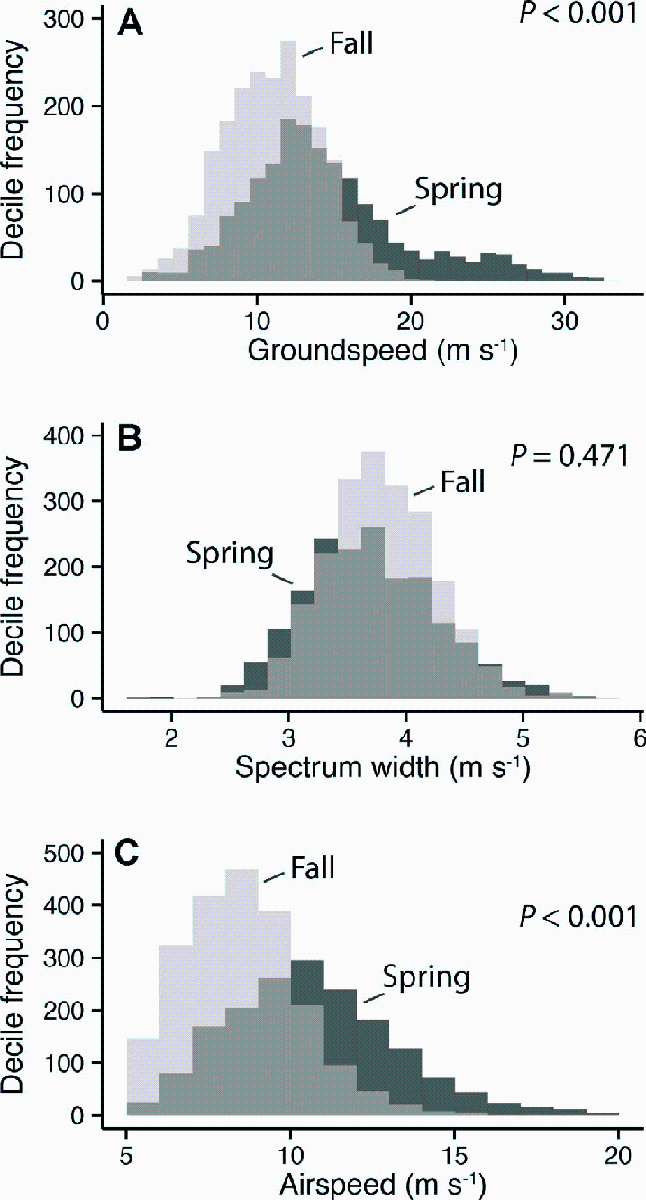

tHorton = table({'Spring';'Autumn'},[14.7; 10.6],[10.6; 8.3],'VariableNames',{'Season','Groundspeed','Airspeed'});
tHorton = [tHorton; table({'Ratio'}, tHorton{1,2}./tHorton{2,2}, tHorton{1,3}./tHorton{2,3},'VariableNames',{'Season','Groundspeed','Airspeed'})];
tHorton.ratio = tHorton.Groundspeed./tHorton.Airspeed

tHorton = 3×4 table
      Season      Groundspeed    Airspeed    ratio 
    __________    ___________    ________    ______

    {'Spring'}        14.7          10.6     1.3868
    {'Autumn'}        10.6           8.3     1.2771
    {'Ratio' }      1.3868        1.2771     1.0859


tUs =table({'Spring';'Autumn'},[12.6;9.89],[8.73;8.24],'VariableNames',{'Season','Groundspeed','Airspeed'});
tUs = [tUs; table({'Ratio'}, tUs{1,2}./tUs{2,2}, tUs{1,3}./tUs{2,3},'VariableNames',{'Season','Groundspeed','Airspeed'})];
tUs.ratio = tUs.Groundspeed./tUs.Airspeed

tUs = 3×4 table
      Season      Groundspeed    Airspeed    ratio 
    __________    ___________    ________    ______

    {'Spring'}        12.6          8.73     1.4433
    {'Autumn'}        9.89          8.24     1.2002
    {'Ratio' }       1.274        1.0595     1.2025


- Generally similar range of value for airpseed and groundspeed (8-14m/s)

- Similar range of ratio (1-1.4).

- Same ratio of groundspeed faster than airspeed (1.4 in Spring and 1.2 in Autumn)

- Same ratio of spring faster than autumn for groundspeed (1.27-1.38)

- But different ratio for airpseed 1.27 for them and 1.06 for us! 

What happen if we filter the airspeed with 5 m/s

ags_tmp = abs(gs); ags_tmp(abs(as)<5)=nan;
aas_tmp = abs(as); aas_tmp(abs(as)<5)=nan;
[~,~,Mg_t_sp] = histvdens(ags_tmp(id_sp,:,:),dens(id_sp,:,:));
[~,~,Mg_t_au] = histvdens(ags_tmp(id_au,:,:),dens(id_au,:,:));
[~,~,Ma_t_sp] = histvdens(aas_tmp(id_sp,:,:),dens(id_sp,:,:));
[~,~,Ma_t_au] = histvdens(aas_tmp(id_au,:,:),dens(id_au,:,:));
table({'Spring';'Autumn';'Ratio'},[Mg_t_sp;Mg_t_au;Mg_t_sp/Mg_t_au],[Ma_t_sp;Ma_t_au;Ma_t_sp/Ma_t_au],'VariableNames',{'Season','Groundspeed','Airspeed'})

ans = 3×3 table
      Season      Groundspeed    Airspeed
    __________    ___________    ________

    {'Spring'}      13.362        9.6046 
    {'Autumn'}      10.351         8.997 
    {'Ratio' }       1.291        1.0675 


The filtering is not really explaning much of this difference between their result and ours... 

Comparing to Kemp et al. (2011)

 Kemp, M.U.; Shamoun-Baranes, J.; Van Gasteren, H.; Bouten, W.; Van Loon, E.E. Can wind help explain seasonal differences in avian migration speed? *J. Avian Biol.* **2010**, *41*, 672–677. DOI:[10.1111/j.1600-048X.2010.05053.x](http://doi.org/10.1111/j.1600-048X.2010.05053.x)

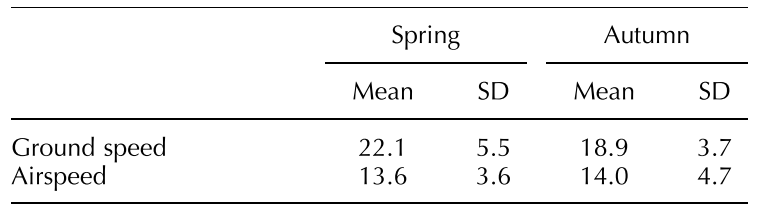

Comparing that to all our radar

tmp_id_sp = dc_time>datetime('1-Feb-2018') & dc_time<datetime('1-June-2018');
tmp_id_au = dc_time>datetime('1-August-2018') & dc_time<datetime('1-Dec-2018');
[~,~,Mgsp,SDgsp] = histvdens(abs(gs(tmp_id_sp,:,:)),dens(tmp_id_sp,:,:));
[~,~,Mgau,SDgau] = histvdens(abs(gs(tmp_id_au,:,:)),dens(tmp_id_au,:,:));
[~,~,Masp,SDasp] = histvdens(abs(as(tmp_id_sp,:,:)),dens(tmp_id_sp,:,:));
[~,~,Maau,SDaau] = histvdens(abs(as(tmp_id_au,:,:)),dens(tmp_id_au,:,:));
table({'Ground speed' ;'Airspeed'},[Mgsp;Masp],[SDgsp;SDasp],[Mgau;Maau],[SDgau;SDaau],'VariableNames',{' ','Spring Mean','Spring SD','Autumn Mean','Autumn SD'})

ans = 2×5 table
                        Spring Mean    Spring SD    Autumn Mean    Autumn SD
    ________________    ___________    _________    ___________    _________

    {'Ground speed'}      12.164        5.8321         9.809        4.3958  
    {'Airspeed'    }      8.7214        3.2649        8.2943        2.9283  


Only Dutch Radar

id_g = contains(dc_name,'nl');
[~,~,Mgsp,SDgsp] = histvdens(abs(gs(tmp_id_sp,:,id_g)),dens(tmp_id_sp,:,id_g));
[~,~,Mgau,SDgau] = histvdens(abs(gs(tmp_id_au,:,id_g)),dens(tmp_id_au,:,id_g));
[~,~,Masp,SDasp] = histvdens(abs(as(tmp_id_sp,:,id_g)),dens(tmp_id_sp,:,id_g));
[~,~,Maau,SDaau] = histvdens(abs(as(tmp_id_au,:,id_g)),dens(tmp_id_au,:,id_g));
table({'Ground speed' ;'Airspeed'},[Mgsp;Masp],[SDgsp;SDasp],[Mgau;Maau],[SDgau;SDaau],'VariableNames',{' ','Spring Mean','Spring SD','Autumn Mean','Autumn SD'})

ans = 2×5 table
                        Spring Mean    Spring SD    Autumn Mean    Autumn SD
    ________________    ___________    _________    ___________    _________

    {'Ground speed'}      9.9961        5.9742        8.8452          4.77  
    {'Airspeed'    }      8.4631        3.6021        8.6385        3.5328  


- Speed much smaller for us, but similar variance (tracking vs radar?)

- Ratio relatively similar: Groundspeed 20-60% faster than airspeed (more for Spring than Autumn)

- Groundspeed 17% faster in Spring than Autumn (27% for us)

- Airspeed 3% slower in spring than autumn (+5% fo us)

Karlsson (2012) & Karlsson (2011)

 Karlsson, H.; Nilsson, C.; Bäckman, J.; Alerstam, T. Nocturnal passerine migration without tailwind assistance. *Ibis (Lond. 1859).* **2011**, *153*, 485–493.

 Karlsson, H.; Nilsson, C.; Bäckman, J.; Alerstam, T. Nocturnal passerine migrants fly faster in spring than in autumn: A test of the time minimization hypothesis. *Anim. Behav.* **2012**, *83*, 87–93.

tK=table({'Spring Lund';'Autumn Lund';'Spring Abisko';'Autumn Abisko'},[12.7;10.5;11.3;10.2],[4.2;4.1;4.9;3.3],[11.9;10.5;11.5;9.5],[2.4;2.3;2.5;2.1],[1183;512;827;566],'VariableNames',{'Season','Groundspeed','Grounsdpeed_sd','Airspeed', 'Airspeed_sd','n'});
%[tK; table({'Ratio Lund', 'Ratio Abiska'}, tK.Groundspeed([1 3])./tK.Groundspeed([2 4]), tK.Airspeed([1 3])./tK.Airspeed([2 4]),'VariableNames',{'Season','Groundspeed','Airspeed'})]
tK.ratio = tK.Groundspeed./tK.Airspeed

tK = 4×7 table
         Season          Groundspeed    Grounsdpeed_sd    Airspeed    Airspeed_sd     n       ratio 
    _________________    ___________    ______________    ________    ___________    ____    _______

    {'Spring Lund'  }       12.7             4.2            11.9          2.4        1183     1.0672
    {'Autumn Lund'  }       10.5             4.1            10.5          2.3         512          1
    {'Spring Abisko'}       11.3             4.9            11.5          2.5         827    0.98261
    {'Autumn Abisko'}       10.2             3.3             9.5          2.1         566     1.0737


% tt = (t{1,4}-t{2,4})/sqrt( t{1,5}^2/t{1,6} + t{2,5}^2/t{2,6} )
% nu = ( t{1,5}^2/t{1,6} + t{2,5}^2/t{2,6} )^2 / ( (t{1,5}^2/t{1,6})^2/(t{1,6}-1) + (t{2,5}^2/t{2,6})^2/(t{2,6}-1) )
% p = 1-tcdf(tt,nu)

Ours

tmp_id_sp = dc_time>datetime('24-April-2018') & dc_time<datetime('10-June-2018');
tmp_id_au = dc_time>datetime('25-July-2018') & dc_time<datetime('31-August-2018');
[~,~,Mgsp,SDgsp] = histvdens(abs(gs(tmp_id_sp,:,:)),dens(tmp_id_sp,:,:));
[~,~,Mgau,SDgau] = histvdens(abs(gs(tmp_id_au,:,:)),dens(tmp_id_au,:,:));
[~,~,Masp,SDasp] = histvdens(abs(as(tmp_id_sp,:,:)),dens(tmp_id_sp,:,:));
[~,~,Maau,SDaau] = histvdens(abs(as(tmp_id_au,:,:)),dens(tmp_id_au,:,:));
table({'Ground speed' ;'Airspeed'},[Mgsp;Masp],[SDgsp;SDasp],[Mgau;Maau],[SDgau;SDaau],'VariableNames',{' ','Spring Mean','Spring SD','Autumn Mean','Autumn SD'})

ans = 2×5 table
                        Spring Mean    Spring SD    Autumn Mean    Autumn SD
    ________________    ___________    _________    ___________    _________

    {'Ground speed'}      10.328        5.5756        8.7079        3.3124  
    {'Airspeed'    }      8.3158        3.1197        7.5099         2.537  


Only German Radar

id_g = contains(dc_name,'de');
[~,~,Mgsp,SDgsp] = histvdens(abs(gs(id_sp,:,id_g)),dens(id_sp,:,id_g));
[~,~,Mgau,SDgau] = histvdens(abs(gs(id_au,:,id_g)),dens(id_au,:,id_g));
[~,~,Masp,SDasp] = histvdens(abs(as(id_sp,:,id_g)),dens(id_sp,:,id_g));
[~,~,Maau,SDaau] = histvdens(abs(as(id_au,:,id_g)),dens(id_au,:,id_g));
table({'Ground speed' ;'Airspeed'},[Mgsp;Masp],[SDgsp;SDasp],[Mgau;Maau],[SDgau;SDaau],'VariableNames',{' ','Spring Mean','Spring SD','Autumn Mean','Autumn SD'})

ans = 2×5 table
                        Spring Mean    Spring SD    Autumn Mean    Autumn SD
    ________________    ___________    _________    ___________    _________

    {'Ground speed'}      9.2706        4.5081        8.7949        3.3309  
    {'Airspeed'    }      7.7284        3.1841        8.4887        2.9267  


id_g = contains(dc_name,'fr');
[~,~,Mgsp,SDgsp] = histvdens(abs(gs(id_sp,:,id_g)),dens(id_sp,:,id_g));
[~,~,Mgau,SDgau] = histvdens(abs(gs(id_au,:,id_g)),dens(id_au,:,id_g));
[~,~,Masp,SDasp] = histvdens(abs(as(id_sp,:,id_g)),dens(id_sp,:,id_g));
[~,~,Maau,SDaau] = histvdens(abs(as(id_au,:,id_g)),dens(id_au,:,id_g));
table({'Ground speed' ;'Airspeed'},[Mgsp;Masp],[SDgsp;SDasp],[Mgau;Maau],[SDgau;SDaau],'VariableNames',{' ','Spring Mean','Spring SD','Autumn Mean','Autumn SD'})

ans = 2×5 table
                        Spring Mean    Spring SD    Autumn Mean    Autumn SD
    ________________    ___________    _________    ___________    _________

    {'Ground speed'}      15.106        5.4577        10.638        4.7332  
    {'Airspeed'    }      9.4841        3.1305        8.0639        2.8883  


Ours Early-vs late migration

table({'March';'April';'Aug.-Sep.';'October';'Ratio short-distance';'Ratio long-distance'},[13.9;11.1;9.04;10.6;13.9/10.6;11.1/9.04],[9.18;8.22;7.55;8.85;9.18/8.85;8.22/7.55],'VariableNames',{'Season','Groundspeed','Airspeed'})

ans = 6×3 table
             Season             Groundspeed    Airspeed
    ________________________    ___________    ________

    {'March'               }        13.9          9.18 
    {'April'               }        11.1          8.22 
    {'Aug.-Sep.'           }        9.04          7.55 
    {'October'             }        10.6          8.85 
    {'Ratio short-distance'}      1.3113        1.0373 
    {'Ratio long-distance' }      1.2279        1.0887 


Nilsson 2014 Early-vs late migration (quite difference timing! based on riging at Falsterbo)

- 9/4 -> 24/4

- 25/4 -> 29/5

- 17/8 -> 9/9

- 9/9 -> 20/10

tmp_id_esp = dc_time>datetime('9-April-2018') & dc_time<datetime('24-April-2018');
tmp_id_lsp = dc_time>datetime('9-April-2018') & dc_time<datetime('24-April-2018');
tmp_id_au = dc_time>datetime('25-July-2018') & dc_time<datetime('31-August-2018');
[~,~,Mgsp,SDgsp] = histvdens(abs(gs(tmp_id_sp,:,:)),dens(tmp_id_sp,:,:));
[~,~,Mgau,SDgau] = histvdens(abs(gs(tmp_id_au,:,:)),dens(tmp_id_au,:,:));
[~,~,Masp,SDasp] = histvdens(abs(as(tmp_id_sp,:,:)),dens(tmp_id_sp,:,:));
[~,~,Maau,SDaau] = histvdens(abs(as(tmp_id_au,:,:)),dens(tmp_id_au,:,:));
table({'Ground speed' ;'Airspeed'},[Mgsp;Masp],[SDgsp;SDasp],[Mgau;Maau],[SDgau;SDaau],'VariableNames',{' ','Spring Mean','Spring SD','Autumn Mean','Autumn SD'})

ans = 2×5 table
                        Spring Mean    Spring SD    Autumn Mean    Autumn SD
    ________________    ___________    _________    ___________    _________

    {'Ground speed'}      10.328        5.5756        8.7079        3.3124  
    {'Airspeed'    }      8.3158        3.1197        7.5099         2.537  




table({'Spring-short dist';'Spring-long dist';'Autumn-long dist';'Atumn-short dist';'Ratio short-distance';'Ratio long-distance'},[14.56;12.7;8.77;13.69;14.56/13.69;12.7/8.77],[12.81;11.73;11.21;11.26;12.81/11.26;11.73/11.21],'VariableNames',{'Season','Groundspeed','Airspeed'})

ans = 6×3 table
             Season             Groundspeed    Airspeed
    ________________________    ___________    ________

    {'Spring-short dist'   }       14.56         12.81 
    {'Spring-long dist'    }        12.7         11.73 
    {'Autumn-long dist'    }        8.77         11.21 
    {'Atumn-short dist'    }       13.69         11.26 
    {'Ratio short-distance'}      1.0636        1.1377 
    {'Ratio long-distance' }      1.4481        1.0464 


## Air vs Ground in space

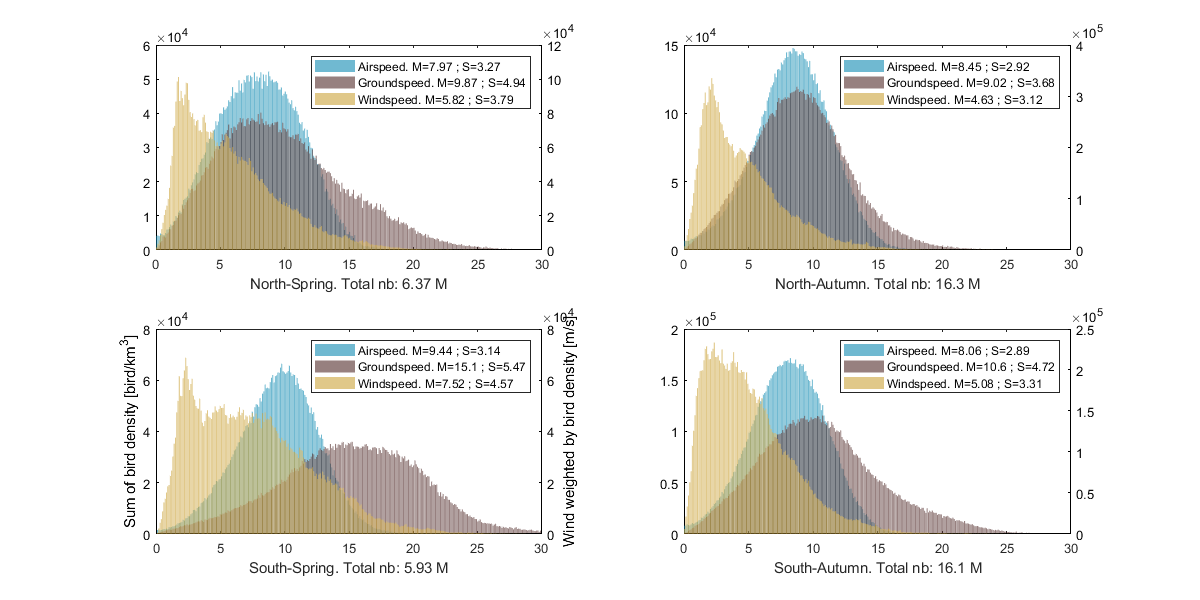

figure('position',[0 0 1200 600]);

subplot(2,2,3); hold on;box on
[b,h,Ma,Sa] = histvdens(abs(as(id_sp,:,id_so)),dens(id_sp,:,id_so));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[b,h,Mg,Sg] = histvdens(abs(gs(id_sp,:,id_so)),dens(id_sp,:,id_so));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
ylabel('Sum of bird density [bird/km^3]');
[b,h,Mw,Sw] = histvdens(abs(ws(id_sp,:,id_so)),dens(id_sp,:,id_so));
yyaxis right; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
%[b,h,Ms,Ss] = histvdens(sd_vvp(id_sp,:,id_so),dens(id_sp,:,id_so));
%yyaxis left; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k'; ylabel('Wind weighted by bird density [m/s]');
legend; xlabel(['South-Spring. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,id_so),3)))/1000000,3) ' M']);

subplot(2,2,4); hold on; box on
[b,h,Ma,Sa] = histvdens(abs(as(id_au,:,id_so)),dens(id_au,:,id_so));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[b,h,Mg,Sg] = histvdens(abs(gs(id_au,:,id_so)),dens(id_au,:,id_so));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[b,h,Mw,Sw] = histvdens(abs(ws(id_au,:,id_so)),dens(id_au,:,id_so));
yyaxis right; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
%[b,h,Ms,Ss] = histvdens(sd_vvp(id_au,:,id_so),dens(id_au,:,id_so));
%yyaxis left; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';xlim([0 30])
legend; xlabel(['South-Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,id_so),3)))/1000000,3) ' M']);

subplot(2,2,1); hold on; box on
[b,h,Ma,Sa] = histvdens(abs(as(id_sp,:,id_no)),dens(id_sp,:,id_no));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[b,h,Mg,Sg] = histvdens(abs(gs(id_sp,:,id_no)),dens(id_sp,:,id_no));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[b,h,Mw,Sw] = histvdens(abs(ws(id_sp,:,id_no)),dens(id_sp,:,id_no));
yyaxis right; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);%[b,h,Ms,Ss] = histvdens(sd_vvp(id_sp,:,id_no),dens(id_sp,:,id_no));
%yyaxis left; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';xlim([0 30])
legend; xlabel(['North-Spring. Total nb: ' num2str(nansum(nansum(nansum(dens(id_sp,:,id_no),3)))/1000000,3) ' M']);

subplot(2,2,2); hold on; box on
[b,h,Ma,Sa] = histvdens(abs(as(id_au,:,id_no)),dens(id_au,:,id_no));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)]);
[b,h,Mg,Sg] = histvdens(abs(gs(id_au,:,id_no)),dens(id_au,:,id_no));
bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)]);
[b,h,Mw,Sw] = histvdens(abs(ws(id_au,:,id_no)),dens(id_au,:,id_no));
yyaxis right; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['Windspeed. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)]);
%[b,h,Ms,Ss] = histvdens(sd_vvp(id_au,:,id_no),dens(id_au,:,id_no));
%yyaxis left; bar(b,h,'FaceAlpha',0.6, 'DisplayName', ['sd_{vvp}. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)]);
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k'; xlim([0 30])
legend; xlabel(['North-Autumn. Total nb: ' num2str(nansum(nansum(nansum(dens(id_au,:,id_no),3)))/1000000,3) ' M']);  

In this figure, we seperate both in term of region: France (top) and Germany (bottom) and Season: Spring (left) and Autumn (right). We also added the windspeed in yellow to help explain the difference between France and Germany.

Groundspeed is suprinsigly much higher in the radar in France, particularly in Spring (15.7 m/s vs 10.8 for Germany). However, airspeed is much more similar between France and Germany (9.6m/s vs 8.3 m/s for Germany). This difference in groundspeed uniquely is well explained by the windspeed (yellow). Indeed, in France birds benefit from a better wind speed (8.7m/s vs 7.1m/s germany) allowing them to increase their groundspeed. 

Note that this windspeed is the norm of the vector and not a projection on the prefered direction of migration. However, it is normalized by the number of bird in the air, thus the windspeed is representative of the wind support of bird migration. 

Is this a pattern unique to 2018? See AverageWind.html

More figures are plotted in Supplementary material down the page. 

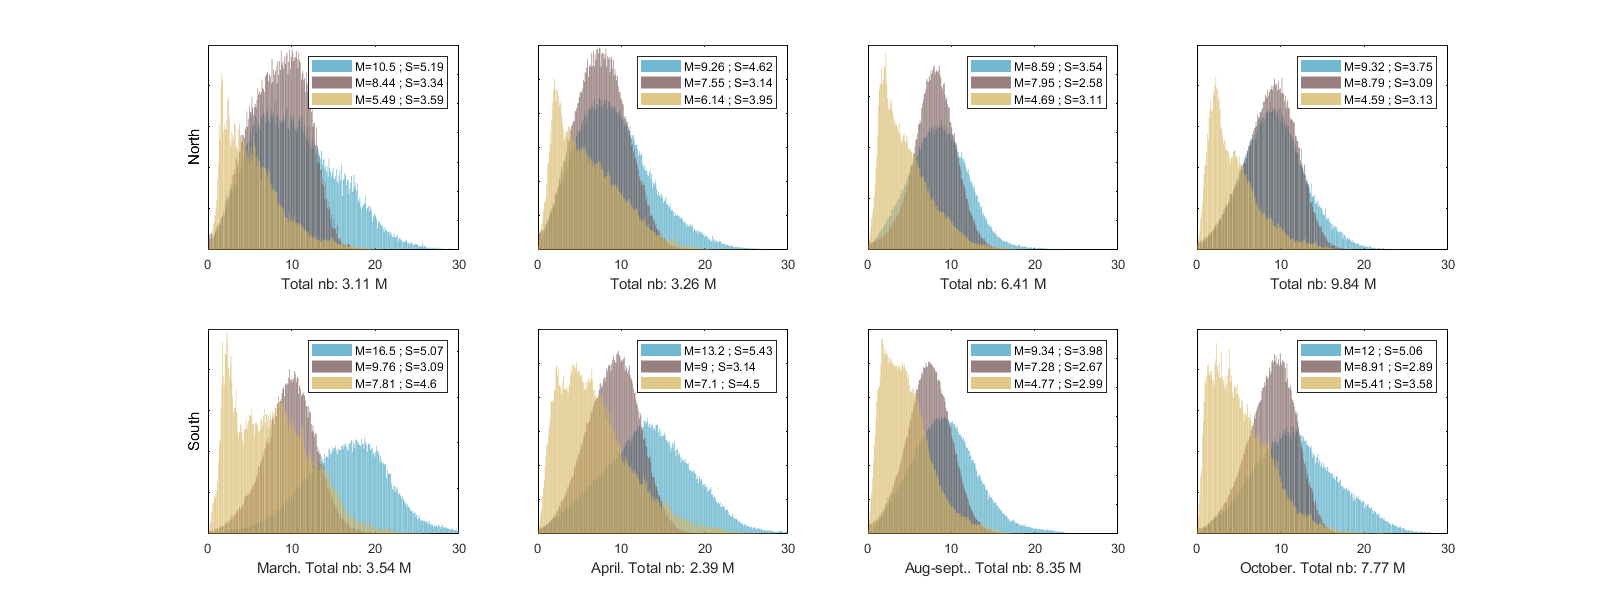

figure('position',[0 0 1600 600]);

for i_s=1:size(id_s,1)
    subplot(2,4,i_s); hold on;
    [b,h,Mg,Sg] = histvdens(abs(gs(id_s(i_s,:),:,id_no)),dens(id_s(i_s,:),:,id_no));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Ma,Sa] = histvdens(abs(as(id_s(i_s,:),:,id_no)),dens(id_s(i_s,:),:,id_no));
    bar(b,h,'FaceAlpha',0.6);
    if i_s==1, ylabel('North'), end
    [b,h,Mw,Sw] = histvdens(abs(ws(id_s(i_s,:),:,id_no)),dens(id_s(i_s,:),:,id_no));
    ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(b,h,'FaceAlpha',0.6); 
    ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel(['Total nb: ' num2str(nansum(nansum(nansum(dens(id_s(i_s,:),:,id_no),3)))/1000000,3) ' M']);xlim([0 30]); box on;

    subplot(2,4,i_s+4); hold on;
    [b,h,Mg,Sg] = histvdens(abs(gs(id_s(i_s,:),:,id_so)),dens(id_s(i_s,:),:,id_so));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Ma,Sa] = histvdens(abs(as(id_s(i_s,:),:,id_so)),dens(id_s(i_s,:),:,id_so));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Mw,Sw] = histvdens(abs(ws(id_s(i_s,:),:,id_so)),dens(id_s(i_s,:),:,id_so));
    if i_s==1, ylabel('South'), end
    ax = gca; set(ax,'yticklabel',[]); yyaxis right; bar(b,h,'FaceAlpha',0.6); 
    ax = gca; set(ax,'yticklabel',[]); ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ['M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel([id_s_name{i_s} '. Total nb: ' num2str(nansum(nansum(nansum(dens(id_s(i_s,:),:,id_so),3)))/1000000,3) ' M']);xlim([0 30]); box on;
end

Mg=nan(ndc,size(id_s,1)); Mwp=Mg; Mgw=Mg; gu=Mg; gv=Mg; gwu=Mg; gwv=Mg; awu=Mg; awv=Mg; wwu=Mg; wwv=Mg; Maw=Mg; Mww=Mg;
Sgw=Mg;Saw=Mg;Sww=Mg;
for i_d = 1:ndc
    for i_s = 1:size(id_s,1)
        Md(i_d,i_s) = nanmean(reshape(dens(id_s(i_s,:),:,i_d),1,[]));
        Mwp(i_d,i_s) = nanmean(reshape(v_wp(id_s(i_s,:),:,i_d),1,[]));
        
        Mg(i_d,i_s) = nanmean(reshape(      abs(gs(id_s(i_s,:),:,i_d)),1,[]));
        gu(i_d,i_s) = nanmean(reshape( real( gs(id_s(i_s,:),:,i_d)),1,[]));
        gv(i_d,i_s) = nanmean(reshape( imag( gs(id_s(i_s,:),:,i_d)),1,[]));
        
        Mw(i_d,i_s) = nanmean(reshape(      abs(ws(id_s(i_s,:),:,i_d)),1,[]));
        wu(i_d,i_s) = nanmean(reshape( real( ws(id_s(i_s,:),:,i_d)),1,[]));
        wv(i_d,i_s) = nanmean(reshape( imag( ws(id_s(i_s,:),:,i_d)),1,[]));
        
        [~,~,Mgw(i_d,i_s),Sgw(i_d,i_s)] = histvdens(      abs(gs(id_s(i_s,:),:,i_d)) ,dens(id_s(i_s,:),:,i_d));
        [~,~,gwu(i_d,i_s)] = histvdens( real( gs(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
        [~,~,gwv(i_d,i_s)] = histvdens( imag( gs(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
        
        [~,~,Maw(i_d,i_s),Saw(i_d,i_s)] = histvdens(      abs(as(id_s(i_s,:),:,i_d)) ,dens(id_s(i_s,:),:,i_d));
        [~,~,awu(i_d,i_s)] = histvdens( real( as(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
        [~,~,awv(i_d,i_s)] = histvdens( imag( as(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
        
        [~,~,Mww(i_d,i_s),Sww(i_d,i_s)] = histvdens(      abs(ws(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
        [~,~,wwu(i_d,i_s)] = histvdens( real( ws(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
        [~,~,wwv(i_d,i_s)] = histvdens( imag( ws(id_s(i_s,:),:,i_d)),dens(id_s(i_s,:),:,i_d));
    end
end

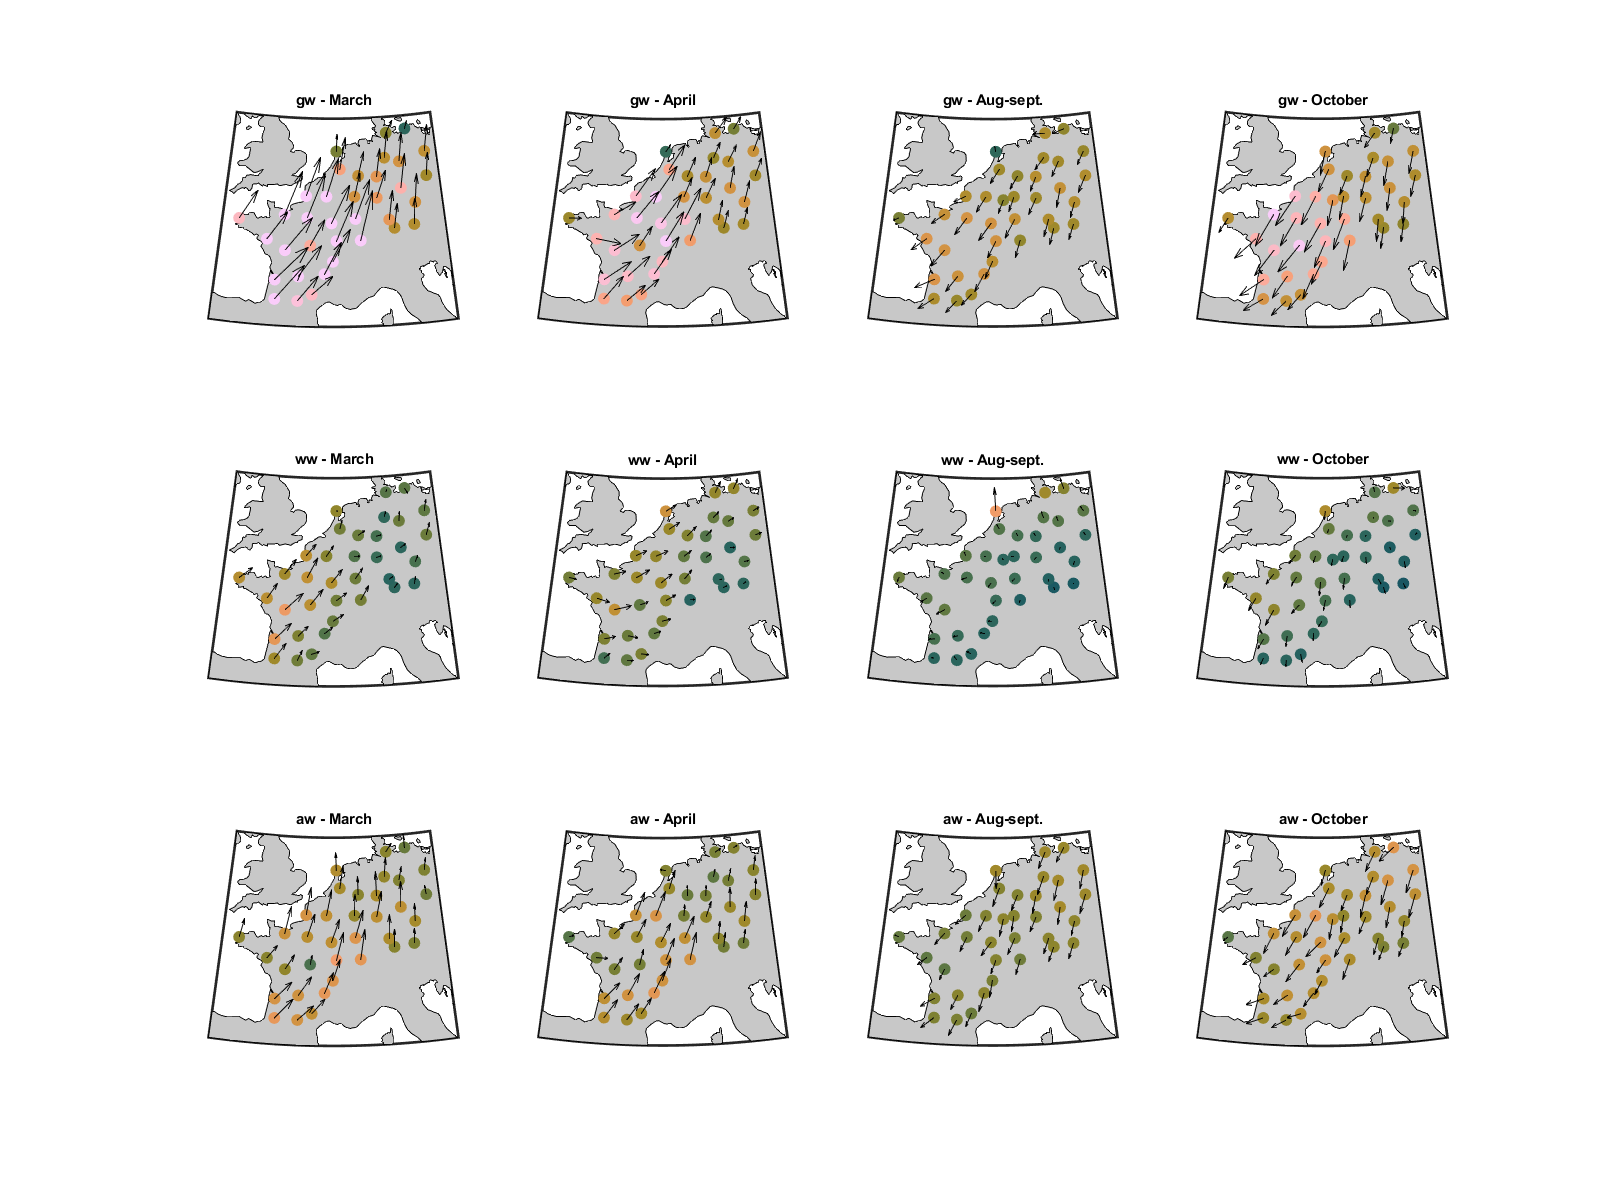

%pplot = {'w','ww','gw','aw','wp','d'};
pplot = {'gw','ww','aw'};

figure('position',[0 0 1600 400*numel(pplot)]); 

for i_p =1:numel(pplot)
    tmp=eval(['M' pplot{i_p}]);
    for i_s = 1:size(id_s,1)
        subplot(numel(pplot),4,4*(i_p-1)+i_s); hold on; 
        h=worldmap([floor(min(dc_lat)-1) ceil(max(dc_lat))], [floor(min(dc_lon)-1) ceil(max(dc_lon))+1]);
        setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
        geoshow('landareas.shp', 'FaceColor', [200 200 200]./255);
        % plotm(coastlat, coastlon,'k'); % geoshow('worldrivers.shp','Color', 'blue');
        scatterm(dc_lat',dc_lon',80,tmp(:,i_s),'filled');
        % scatterm([dc(id_de).lat]',[dc(id_de).lon]',100,tmp(id_de,i_s),'filled');
        % scatterm([dc(~id_de&~id_fr).lat]',[dc(~id_de&~id_fr).lon]',100,tmp(~id_de&~id_fr,i_s),'s','filled');
        % scatterm([dc(id_fr).lat]',[dc(id_fr).lon]',100,tmp(id_fr,i_s),'d','filled');  
        title([pplot{i_p} ' - ' id_s_name{i_s}]);
        if exist([pplot{i_p} 'u'])
            tmpu=eval([pplot{i_p} 'u']);
            tmpv=eval([pplot{i_p} 'v']);
            quiverm(dc_lat',dc_lon',tmpu(:,i_s)/5,tmpv(:,i_s)/5,'k',0);
        end
        caxis([0 15])
        if pplot{i_p}=='wp'
            tmp2 = sqrt(tmp(:,i_s).^2/2);
            quiverm(dc_lat',dc_lon',tmp2/5,tmp2/5,'k',0);
            %colormap(gca,magma)
        elseif pplot{i_p}=='d'
            colormap(gca,viridis)
            caxis([0 10])
        end
    end
end

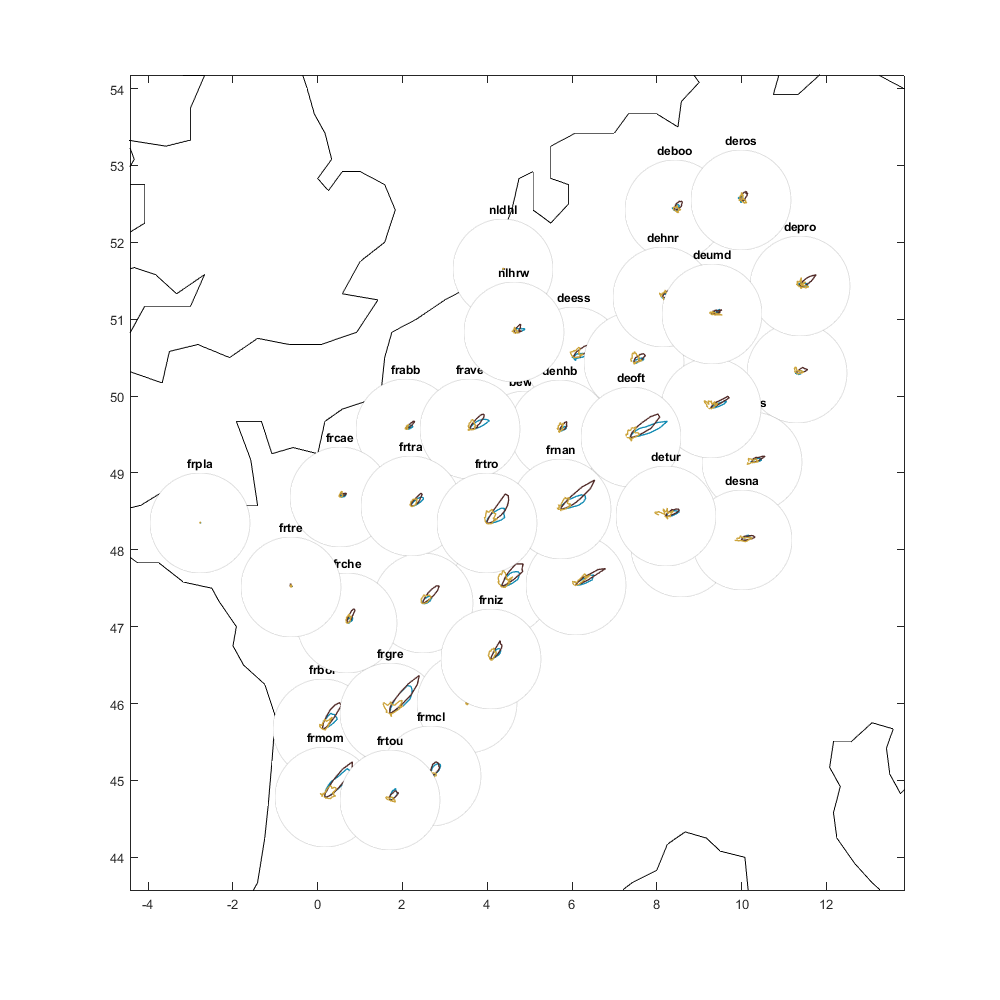

w=.15; h=0.10; m =.2; 
pw = @(lon) (lon-min(dc_lon))/(max(dc_lon)-min(dc_lon))*(1-2*m)+m;
ph = @(lat) (lat-min(dc_lat))/(max(dc_lat)-min(dc_lat))*(1-2*m)+m;

figure('position',[0 0 1000 1000]);
plot(coastlon,coastlat,'-k');
% geoshow('landareas.shp', 'FaceColor', [200 200 200]./255);
xlim([min(dc_lon) max(dc_lon)])
ylim([min(dc_lat) max(dc_lat)])
 
 for i_d=1:ndc
    subAX = axes('position',[pw(dc_lon(i_d))-w/2 ph(dc_lat(i_d))-h/2 w h]);

    %[esp,hsp,~,~,Mdd(i_d,1)] = histvdens(dc(i_d).dd(id_sp,:), dens(id_sp,:,i_d).*abs(gs)(id_sp,:,i_d), 100);
    %[eau,hau,~,~,Mdd(i_d,2)] = histvdens(dc(i_d).dd(id_au,:), dens(id_au,:,i_d).*abs(gs)(id_au,:,i_d), 100);
    [b,h2] = histVdens(as(id_sp,:,i_d), dens(id_sp,:,i_d));
    polarplot(b,h2,'Color',colorder(1,:),'linewidth',1); hold on;
    [b,h2] = histVdens(gs(id_sp,:,i_d), dens(id_sp,:,i_d));
    polarplot(b,h2,'Color',colorder(2,:),'linewidth',1); 
    [b,h2] = histVdens(ws(id_sp,:,i_d), dens(id_sp,:,i_d));
    polarplot(b,h2,'Color',colorder(3,:),'linewidth',1); 

    Ax = gca; Ax.ThetaGrid = 'off'; Ax.RGrid='off'; Ax.RTickLabel = []; Ax.ThetaTickLabel = [];
    title(dc_name{i_d});%,'Color',id_sno_col(id_no(i_d)+1,:))
    Ax.RLim=[0 1e5];
 end

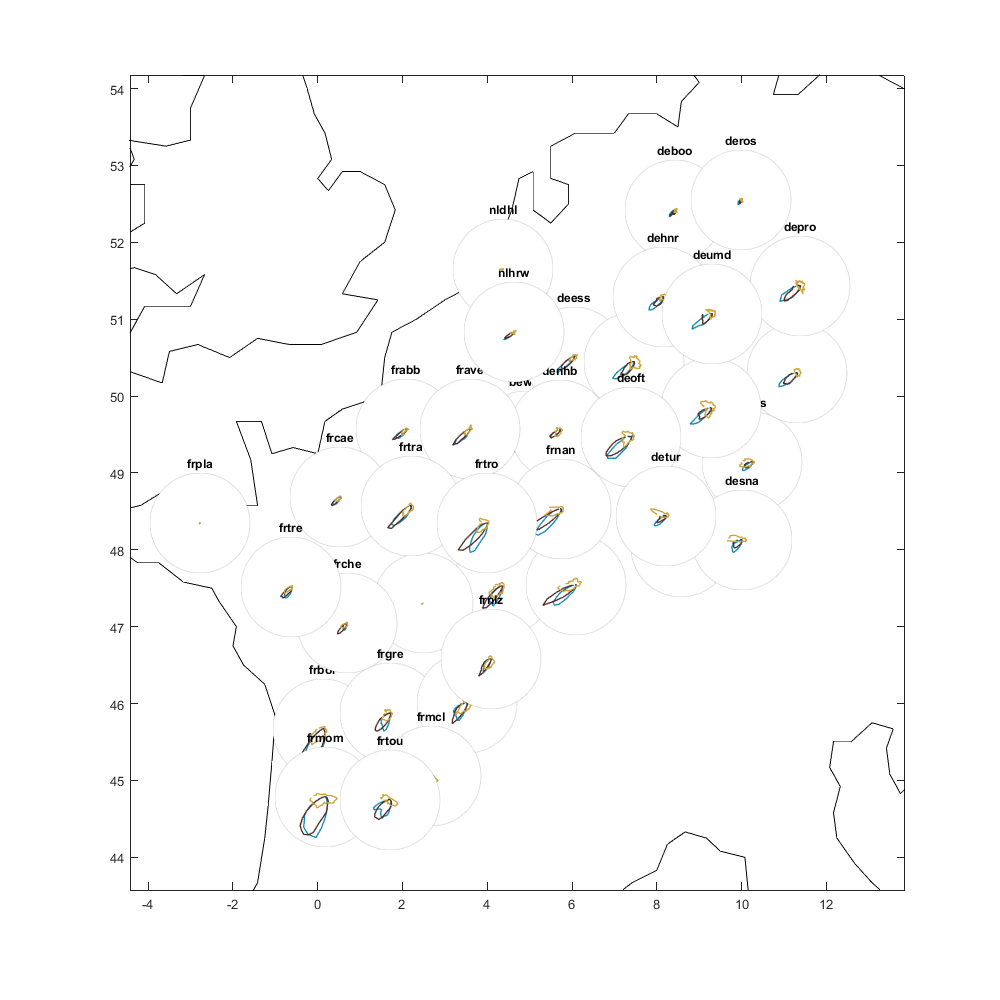

figure('position',[0 0 1000 1000]);
plot(coastlon,coastlat,'-k');
% geoshow('landareas.shp', 'FaceColor', [200 200 200]./255);
xlim([min(dc_lon) max(dc_lon)])
ylim([min(dc_lat) max(dc_lat)])
 
 for i_d=1:ndc
    subAX = axes('position',[pw(dc_lon(i_d))-w/2 ph(dc_lat(i_d))-h/2 w h]);

    
    [b,h2] = histVdens(as(id_au,:,i_d), dens(id_au,:,i_d));
    polarplot(b,h2,'Color',colorder(1,:),'linewidth',1);  hold on;
    [b,h2] = histVdens(gs(id_au,:,i_d), dens(id_au,:,i_d));
    polarplot(b,h2,'Color',colorder(2,:),'linewidth',1);
    [b,h2] = histVdens(ws(id_au,:,i_d), dens(id_au,:,i_d));
    polarplot(b,h2,'Color',colorder(3,:),'linewidth',1);
    
    Ax = gca; Ax.ThetaGrid = 'off'; Ax.RGrid='off'; Ax.RTickLabel = []; Ax.ThetaTickLabel = [];
    title(dc_name(i_d));%,'Color',id_sno_col(id_no(i_d)+1,:))
    Ax.RLim=[0 2e5];
    
 end

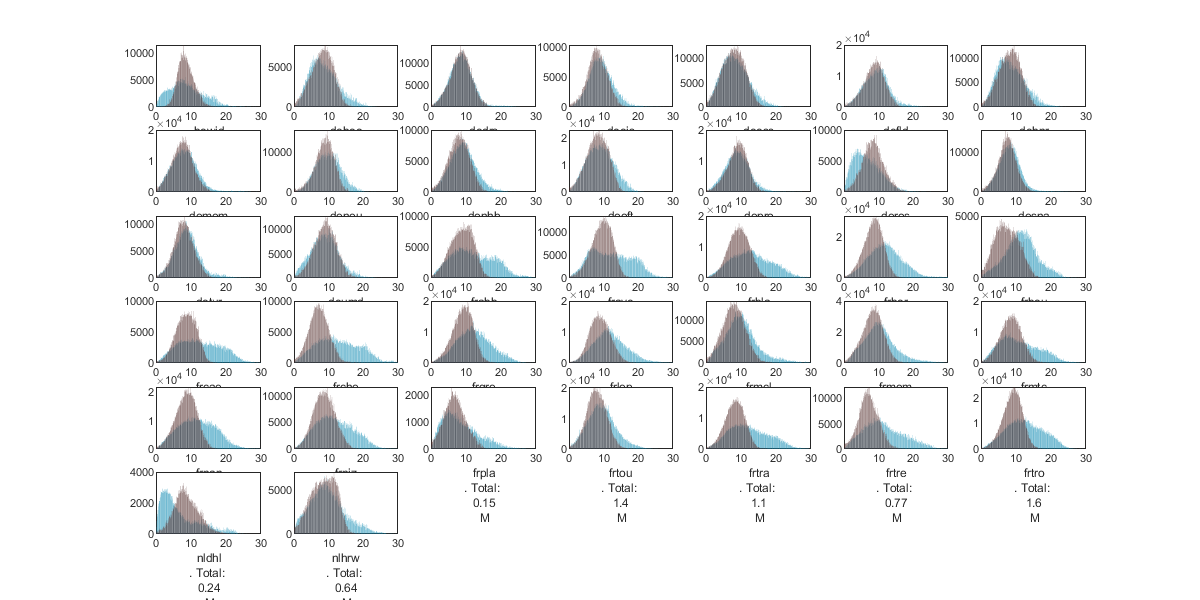

figure('position',[0 0 1200 600]);
Mg=nan(1,ndc);Sg=Mg;Ma=Mg;Sa=Mg;Mw=Mg;Sw=Mg;
for i_d= 1:ndc
    subplot(6,7,i_d); hold on
    [b,h,Mg(i_d), Sg(i_d)] = histvdens(abs(gs(:,:,i_d)),dens(:,:,i_d));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Ma(i_d), Sa(i_d)] = histvdens(abs(as(:,:,i_d)),dens(:,:,i_d));
    bar(b,h,'FaceAlpha',0.6);
    histogram(abs(gs(:,:,i_d)),'Normalization', 'pdf','FaceAlpha',0.6,'EdgeAlpha',0)
    %[e,h,Mw(i_d), Sw(i_d)] = histvdens(v_w(:,:,i_d),dens(:,:,i_d));
    %bar(e,h,'FaceAlpha',0.6);
    % legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)])
    xlabel([ dc_name(i_d) '. Total: ' num2str(sum(h)/1000000,2) ' M']); xlim([0 30]); box on;
end

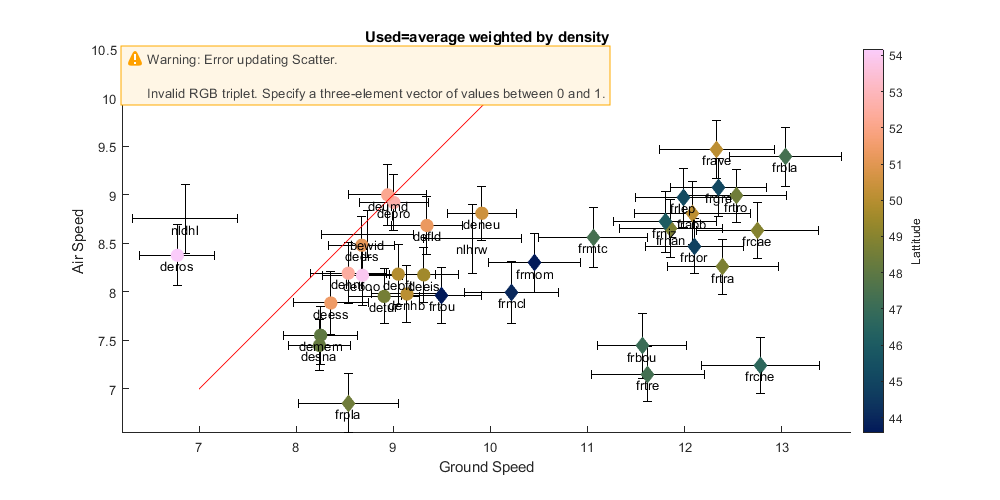

figure('position',[0 0 1000 500]); 
% subplot(2,1,1);
hold on;
eb(1) = errorbar(Mg,Ma,Sg/10, 'horizontal', 'LineStyle', 'none','Color','k');
eb(2) = errorbar(Mg,Ma,Sa/10, 'vertical', 'LineStyle', 'none','Color','k');
scatter(Mg(id_de),Ma(id_de),100,dc_lat(id_de),'filled');
scatter(Mg(~id_de&~id_fr),Ma(~id_de&~id_fr),100,dc_lat(~id_de&~id_fr),'s','filled');
scatter(Mg(id_fr),Ma(id_fr),100,dc_lat(id_fr),'d','filled');
plot([7 10.5],[7 10.5],'-r')
text(Mg,Ma-0.1,dc_name,'HorizontalAlignment','center')
axis equal; xlabel('Ground Speed');ylabel('Air Speed');
c=colorbar(); c.Label.String = 'Lattitude';
title('Used=average weighted by density')

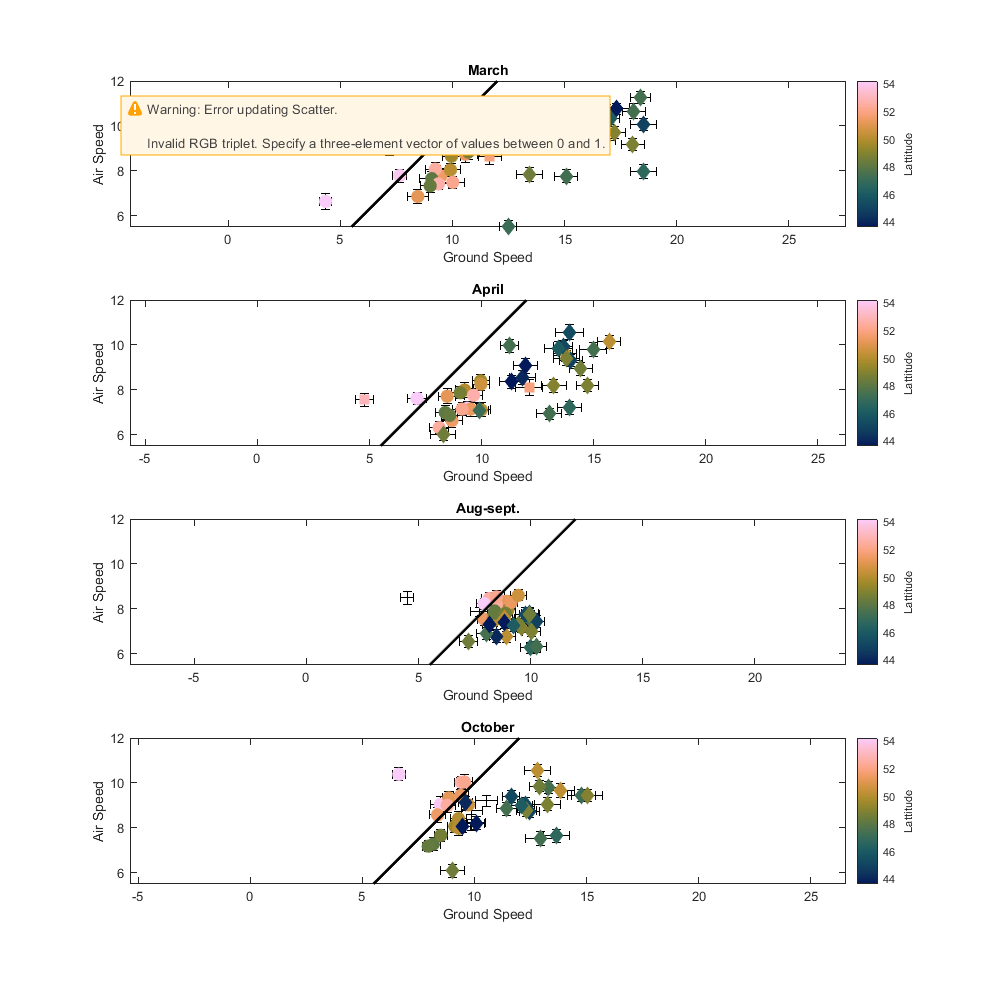

% subplot(2,1,2); hold on;
% Mg2=nanmean(reshape(abs(gs),[],ndc));
% Ma2=nanmean(reshape(abs(as),[],ndc));
% Sg2=nanstd(reshape(abs(gs),[],ndc));
% Sa2=nanstd(reshape(abs(as),[],ndc));
% eb(1) = errorbar(Mg2,Ma2,Sg2/10, 'horizontal', 'LineStyle', 'none','Color','k');
% eb(2) = errorbar(Mg2,Ma2,Sa2/10, 'vertical', 'LineStyle', 'none','Color','k');
% scatter(Mg2(id_de),Ma2(id_de),100,[dc(id_de).lat],'filled');
% scatter(Mg2(~id_de&~id_fr),Ma2(~id_de&~id_fr),100,[dc(~id_de&~id_fr).lat],'s','filled');
% scatter(Mg2(id_fr),Ma2(id_fr),100,[dc(id_fr).lat],'d','filled');
% plot([7 10.5],[7 10.5],'-r')
% text(Mg2,Ma2-0.1,{dc.name},'HorizontalAlignment','center')
% axis equal; xlabel('Ground Speed');ylabel('Air Speed');
% c=colorbar(); c.Label.String = 'Lattitude'; title('Available')
figure('position',[0 0 1000 1000]); 
for i_s=1:4
    subplot(4,1,i_s);hold on;
    eb(1) = errorbar(Mgw(:,i_s),Maw(:,i_s),Sgw(:,i_s)/10, 'horizontal', 'LineStyle', 'none','Color','k');
    eb(2) = errorbar(Mgw(:,i_s),Maw(:,i_s),Saw(:,i_s)/10, 'vertical', 'LineStyle', 'none','Color','k');
    scatter(Mgw(id_de&~isnan(Mgw(:,i_s)),i_s),Maw(id_de&~isnan(Mgw(:,i_s)),i_s),100,dc_lat(id_de&~isnan(Mgw(:,i_s))),'filled');
    scatter(Mgw(~id_de&~id_fr&~isnan(Mgw(:,i_s)),i_s),Maw(~id_de&~id_fr&~isnan(Mgw(:,i_s)),i_s),100,dc_lat(~id_de&~id_fr&~isnan(Mgw(:,i_s))),'s','filled');
    scatter(Mgw(id_fr&~isnan(Mgw(:,i_s)),i_s),Maw(id_fr&~isnan(Mgw(:,i_s)),i_s),100,dc_lat(id_fr&~isnan(Mgw(:,i_s))),'d','filled');
    plot([0 20],[0 20],'-k','linewidth',2)
    % text(Mgw(:,i_s),Maw(:,i_s)-0.1,{dc.name},'HorizontalAlignment','center')
    xlim([5 19]); ylim([5.5 12]);
    axis equal; xlabel('Ground Speed');ylabel('Air Speed');
    c=colorbar(); c.Label.String = 'Lattitude';
    title(id_s_name{i_s}); box on;
end

There is a very strong difference visible at the country level. In Germany, the difference between airspeed and ground speed is very small while in French, the pattern observed earlier is most consistant.

## Air vs Ground in a**ltitude**

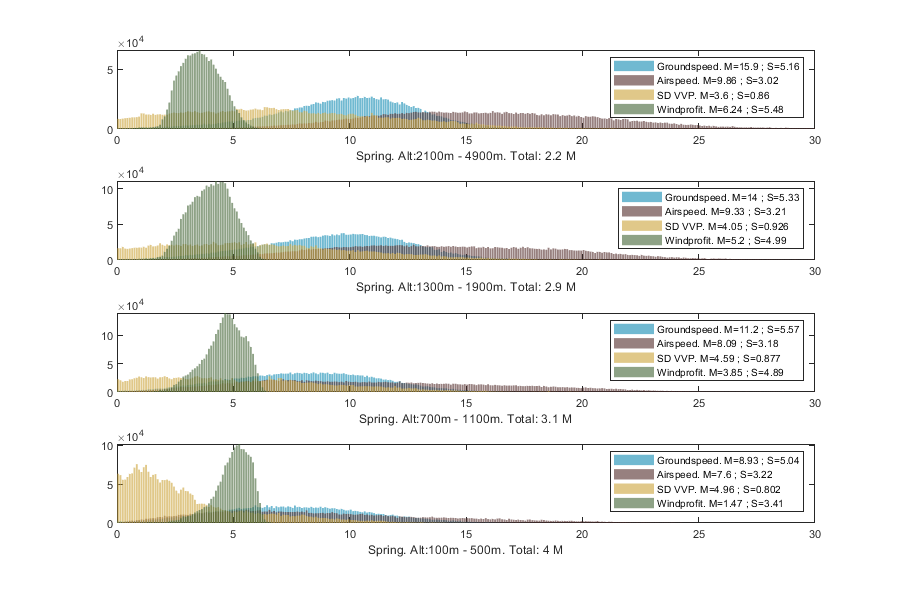

a = [0 600 1200 2000 5000];
figure('position',[0 0 900 600]);
for i_a= 1:numel(a)-1
    id_a = dc_alt>a(i_a) & dc_alt<=a(i_a+1);
    subplot(numel(a)-1,1,numel(a)-i_a); hold on; box on;
    [b,h,Ma,Sa] = histvdens(abs(as(id_sp,id_a,:)),dens(id_sp,id_a,:));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Mg,Sg] = histvdens(abs(gs(id_sp,id_a,:)),dens(id_sp,id_a,:));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Mw,Sw] = histvdens(v_wp(id_sp,id_a,:),dens(id_sp,id_a,:));
    % yyaxis right; 
    bar(b,h,'FaceAlpha',0.6);
    [b,h, Ms, Ss ] = histvdens(sd_vvp(id_sp,id_a,:),dens(id_sp,id_a,:));
    % yyaxis left; ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k'; 
    bar(b,h,'FaceAlpha',0.6);
    
    legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ...
    ['SD VVP. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)], ['Windprofit. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel(['Spring. Alt:' num2str(min(dc_alt(id_a))) 'm - ' num2str(max(dc_alt(id_a))) 'm. Total: ' num2str(nansum(nansum(nansum(dens(id_sp,id_a,:),3)))/1000000,2) ' M']); xlim([0 30]);
end

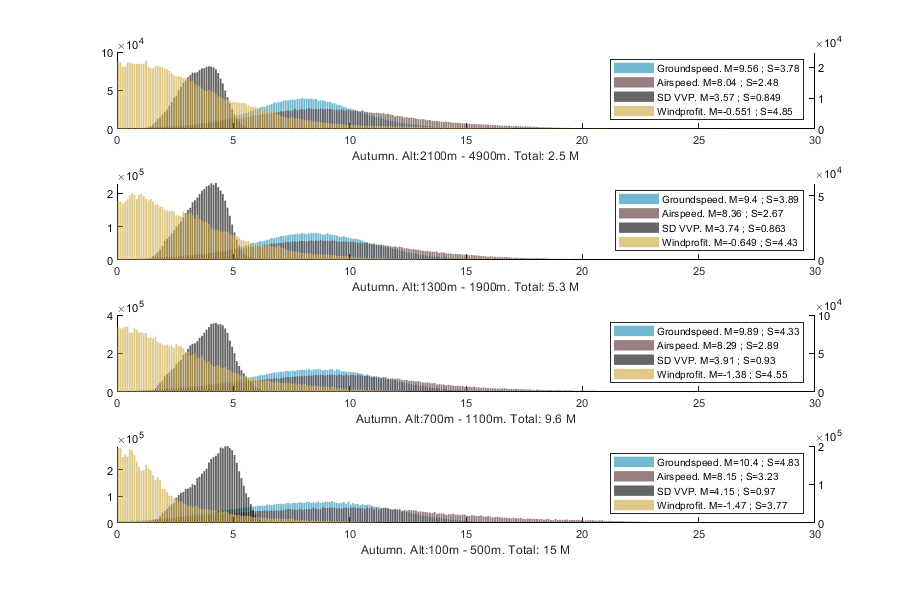

a = [0 600 1200 2000 5000];
figure('position',[0 0 900 600]);
 for i_a= 1:numel(a)-1
    id_a = dc_alt>a(i_a) & dc_alt<=a(i_a+1);
    subplot(numel(a)-1,1,numel(a)-i_a); hold on
    [b,h,Ma,Sa] = histvdens(abs(as(id_au,id_a,:)),dens(id_au,id_a,:));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Mg,Sg] = histvdens(abs(gs(id_au,id_a,:)),dens(id_au,id_a,:));
    bar(b,h,'FaceAlpha',0.6);
    [b,h,Mw,Sw] = histvdens(v_wp(id_au,id_a,:),dens(id_au,id_a,:));
    yyaxis right; bar(b,h,'FaceAlpha',0.6);
    [b,h, Ms, Ss] = histvdens(sd_vvp(id_au,id_a,:),dens(id_au,id_a,:));
    yyaxis left; bar(b,h,'FaceAlpha',0.6);
    ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
    legend(['Groundspeed. M=' num2str(Mg,3) ' ; S=' num2str(Sg,3)], ['Airspeed. M=' num2str(Ma,3) ' ; S=' num2str(Sa,3)], ...
    ['SD VVP. M=' num2str(Ms,3) ' ; S=' num2str(Ss,3)], ['Windprofit. M=' num2str(Mw,3) ' ; S=' num2str(Sw,3)])
    xlabel(['Autumn. Alt:' num2str(min(dc_alt(id_a))) 'm - ' num2str(max(dc_alt(id_a))) 'm. Total: ' num2str(nansum(nansum(nansum(dens(id_au,id_a,:),3)))/1000000,2) ' M']); xlim([0 30]);
end

Mg = nan(numel(dc_alt),ndc,2);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(dc_alt)
     for i_d=1:ndc
        [~,~,Mg(i_a,i_d,1), Sg(i_a,i_d,1)] = histvdens(abs(gs(id_sp,i_a,i_d)),dens(id_sp,i_a,i_d));
        [~,~,Ma(i_a,i_d,1), Sa(i_a,i_d,1)] = histvdens(abs(as(id_sp,i_a,i_d)),dens(id_sp,i_a,i_d));
        % [~,~,Mw(i_a,i_d,1), Sw(i_a,i_d,1)] = histvdens(v_wp(id_sp,i_a,i_d),dens(id_sp,i_a,i_d));
        [~,~,Mw(i_a,i_d,1), Sw(i_a,i_d,1)] = histvdens(abs(ws(id_sp,i_a,i_d)),dens(id_sp,i_a,i_d));
        [~,~,Ms(i_a,i_d,1), Ss(i_a,i_d,1)] = histvdens(sd_vvp(id_sp,i_a,i_d),dens(id_sp,i_a,i_d));
        [~,~,Md(i_a,i_d,1), Sd(i_a,i_d,1)] = histvdens(dens(id_sp,i_a,i_d),dens(id_sp,i_a,i_d));

        [~,~,Mg(i_a,i_d,2), Sg(i_a,i_d,2)] = histvdens(abs(gs(id_au,i_a,i_d)),dens(id_au,i_a,i_d));
        [~,~,Ma(i_a,i_d,2), Sa(i_a,i_d,2)] = histvdens(abs(as(id_au,i_a,i_d)),dens(id_au,i_a,i_d));
        % [~,~,Mw(i_a,i_d,2), Sw(i_a,i_d,2)] = histvdens(-v_wp(id_au,i_a,i_d),dens(id_au,i_a,i_d));
        [~,~,Mw(i_a,i_d,2), Sw(i_a,i_d,2)] = histvdens(abs(ws(id_au,i_a,i_d)),dens(id_au,i_a,i_d));
        [~,~,Ms(i_a,i_d,2), Ss(i_a,i_d,2)] = histvdens(sd_vvp(id_au,i_a,i_d),dens(id_au,i_a,i_d));
        [~,~,Md(i_a,i_d,2), Sd(i_a,i_d,2)] = histvdens(dens(id_au,i_a,i_d),dens(id_au,i_a,i_d));
     end
end

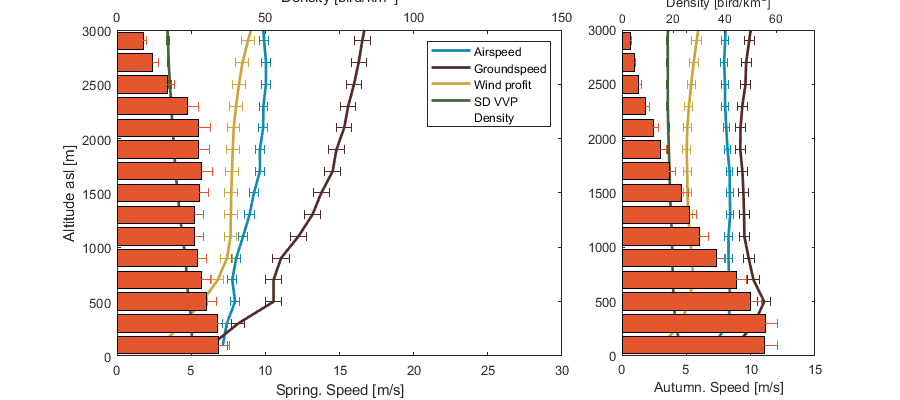

clear l
figure('position',[0 0 900 400]);
subplot(1,3,[1 2]); hold on; box on;
tmp = errorbar(Ma(:,1),dc_alt,Sa(:,1)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(1,:)); l(1)=plot(Ma(:,1),dc_alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mg(:,1),dc_alt,Sg(:,1)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(2,:)); l(2)=plot(Mg(:,1),dc_alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,1),dc_alt,Sw(:,1)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(3,:)); l(3)=plot(Mw(:,1),dc_alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,1),dc_alt,Ss(:,1)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(4,:)); l(4)=plot(Ms(:,1),dc_alt,'-','Color',tmp.Color,'LineWidth',2); 
xlim([0 30]);ylabel('Altitude asl [m]'); xlabel('Spring. Speed [m/s]'); ylim([0 3000]); 
ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on; 
l(5)=barh(dc_alt,Md(:,1),'FaceColor',colorder(5,:),'Parent',ax2); 
errorbar(Md(:,1),dc_alt,Sd(:,1)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',colorder(5,:));  
xlabel('Density [bird/km^3]'); ylim([0 3000]);  xlim([0 150]); legend(l,{'Airspeed','Groundspeed','Wind profit','SD VVP','Density'});

subplot(1,3,3); hold on; box on
tmp = errorbar(Ma(:,2),dc_alt,Sa(:,2)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(1,:)); l(1)=plot(Ma(:,2),dc_alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mg(:,2),dc_alt,Sg(:,2)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(2,:)); l(2)=plot(Mg(:,2),dc_alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Mw(:,2),dc_alt,Sw(:,2)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(3,:)); l(3)=plot(Mw(:,2),dc_alt,'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(Ms(:,2),dc_alt,Ss(:,2)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(4,:)); l(4)=plot(Ms(:,2),dc_alt,'-','Color',tmp.Color,'LineWidth',2);
xlim([0 15]); xlabel('Autumn. Speed [m/s]'); ylim([0 3000]); ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on;
l(5)=barh(dc_alt,Md(:,2),'FaceColor',colorder(5,:),'Parent',ax2); 
errorbar(Md(:,2),dc_alt,Sd(:,2)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',colorder(5,:)); 
xlabel('Density [bird/km^3]'); ylim([0 3000]); xlim([0 75])

Thick line represent the mean and the error bird the 1 standard deviation computed at each altitude bin and weighted by the density of bird. `sd_vvp` is the variance of groundspeed within the bin. The size of the Spring and Autumn subplot are scaled to have the same axis scale. 

Ground speed generally increase with altitude, but airspeed increase much less as windspeed explain in great part the increase of groundspeed. This effect is visible in both spring and autumn. The profile of groundspeed and windspeed matches well in both season, making the airspeed profile relatively straight (at least in comparison to windspeed and groundspeed). 

The decrease of `sd_vvp` with altitude indicates a more directional flow of bird in high altitude (less variance in groundspeed). This variability is certainly explained by bird flying in more diverse direction at low elevation and consequently reducing the average ground speed (and airspeed!) of the bin as measure by weather radar. One could try to argue that the "angle" (derivative with regard to altitude) in sd_vvp and airspeed are matching (e.g. 100-500m bin in autumn).

Mg = nan(numel(dc_alt),4);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(dc_alt)
    for i_s=1:size(id_s)
        [~,~,Mg(i_a,i_s), Sg(i_a,i_s)] = histvdens(abs(gs(id_s(i_s,:),i_a,:)),dens(id_s(i_s,:),i_a,:));
        [~,~,Ma(i_a,i_s), Sa(i_a,i_s)] = histvdens(abs(as(id_s(i_s,:),i_a,:)),dens(id_s(i_s,:),i_a,:));
        % [~,~,Mw(i_a,i_s), Sw(i_a,i_s)] = histvdens(v_wp(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
        [~,~,Mw(i_a,i_s), Sw(i_a,i_s)] = histvdens(abs(ws(id_s(i_s,:),i_a,:)),dens(id_s(i_s,:),i_a,:));
        [~,~,Ms(i_a,i_s), Ss(i_a,i_s)] = histvdens(sd_vvp(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
        [~,~,Md(i_a,i_s), Sd(i_a,i_s)] = histvdens(dens(id_s(i_s,:),i_a,:),dens(id_s(i_s,:),i_a,:));
    end
end

figure('position',[0 0 1600 600]);
clear l
for i_s=1:size(id_s)
    subplot(1,4,i_s); hold on;
    tmp = errorbar(Ma(:,i_s),dc_alt,Sa(:,i_s)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(1,:)); l(1)=plot(Ma(:,i_s),dc_alt,'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(Mg(:,i_s),dc_alt,Sg(:,i_s)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(2,:)); l(2)=plot(Mg(:,i_s),dc_alt,'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(Mw(:,i_s),dc_alt,Sw(:,i_s)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(3,:)); l(3)=plot(Mw(:,i_s),dc_alt,'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(Ms(:,i_s),dc_alt,Ss(:,i_s)/10, 'horizontal', 'LineStyle', 'none','Color',colorder(4,:)); l(4)=plot(Ms(:,i_s),dc_alt,'-','Color',tmp.Color,'LineWidth',2); 
    xlim([0 20]);ylabel('Altitude asl [m]'); xlabel([id_s_name{i_s} '. Speed [m/s]']); ylim([0 4000]); 
    ax1=gca; ax2 = axes('Position',ax1.Position,'XAxisLocation','top','Color','none','YTickLabel',[]); hold on;
    tmp = errorbar(Md(:,i_s),dc_alt,Sd(:,i_s)/10, 'horizontal', 'LineStyle', 'none','Parent', ax2,'Color',colorder(5,:)); l(5)=plot(Md(:,i_s),dc_alt,'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',tmp.Color); 
    xlabel('Density [bird/km^3]'); ylim([0 3000]);  xlim([0 80]); legend(l,{'Groundspeed','Airspeed','Windspeed','SD VVP','Density'}); box on;
end

## Air vs Ground in during the** night**

a=-1:0.1:1;
mida=(a(2:end)+a(1:end-1))/2;
Mg = nan(numel(a)-1,2);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(a)-1
    id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1) & repmat(id_sp',1,ndc),[1 3 2]),1,25,1);
    [~,~,Mg(i_a,1), Sg(i_a,1)] = histvdens(abs(gs(id_a)),dens(id_a));
    [~,~,Ma(i_a,1), Sa(i_a,1)] = histvdens(abs(as(id_a)),dens(id_a));
    [~,~,Mw(i_a,1), Sw(i_a,1)] = histvdens(v_w(id_a),dens(id_a));
    [~,~,Ms(i_a,1), Ss(i_a,1)] = histvdens(sd_vvp(id_a),dens(id_a));
    [~,~,Md(i_a,1), Sd(i_a,1)] = histvdens(dens(id_a),dens(id_a));
    id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1) & repmat(id_au',1,ndc),[1 3 2]),1,25,1);
    [~,~,Mg(i_a,2), Sg(i_a,2)] = histvdens(abs(gs(id_a)),dens(id_a));
    [~,~,Ma(i_a,2), Sa(i_a,2)] = histvdens(abs(as(id_a)),dens(id_a));
    [~,~,Mw(i_a,2), Sw(i_a,2)] = histvdens(v_w(id_a),dens(id_a));
    [~,~,Ms(i_a,2), Ss(i_a,2)] = histvdens(sd_vvp(id_a),dens(id_a));
    [~,~,Md(i_a,2), Sd(i_a,2)] = histvdens(dens(id_a),dens(id_a));
end

figure('position',[0 0 900 800]);
subplot(2,1,1); hold on;
tmp = errorbar(mida, Ma(:,1),Sa(:,1)/10, 'vertical', 'LineStyle', 'none','Color',colorder(1,:)); l(1)=plot(mida, Ma(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Mg(:,1),Sg(:,1)/10, 'vertical', 'LineStyle', 'none','Color',colorder(2,:)); l(2)=plot(mida, Mg(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Mw(:,1),Sw(:,1)/10, 'vertical', 'LineStyle', 'none','Color',colorder(3,:)); l(3)=plot(mida, Mw(:,1),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ms(:,1),Ss(:,1)/10, 'vertical', 'LineStyle', 'none','Color',colorder(4,:)); l(4)=plot(mida, Ms(:,1),'-','Color',tmp.Color,'LineWidth',2); 
ylim([3 14]);ylabel('Altitude asl [m]'); ylabel('Spring. Speed [m/s]'); xlim([-1 1]); 
ax1=gca; ax2 = axes('Position',ax1.Position,'YAxisLocation','right','Color','none','XTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(mida, Md(:,1),Sd(:,1)/10, 'vertical', 'LineStyle', 'none','Parent', ax2,'Color',colorder(5,:)); l(5)=plot(mida, Md(:,1),'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',tmp.Color); 
ylabel('Density [bird/km^3]'); xlim([-1 1]);  ylim([0 50]); legend(l,{'Airspeed','Groundspeed','Windspeed','SD VVP','Density'}); box on

subplot(2,1,2); hold on;
tmp = errorbar(mida, Ma(:,2),Sa(:,2)/10, 'vertical', 'LineStyle', 'none','Color',colorder(1,:)); l(1)=plot(mida, Ma(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Mg(:,2),Sg(:,2)/10, 'vertical', 'LineStyle', 'none','Color',colorder(2,:)); l(2)=plot(mida, Mg(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Mw(:,2),Sw(:,2)/10, 'vertical', 'LineStyle', 'none','Color',colorder(3,:)); l(3)=plot(mida, Mw(:,2),'-','Color',tmp.Color,'LineWidth',2); 
tmp = errorbar(mida, Ms(:,2),Ss(:,2)/10, 'vertical', 'LineStyle', 'none','Color',colorder(4,:)); l(4)=plot(mida, Ms(:,2),'-','Color',tmp.Color,'LineWidth',2);
ylim([3 14]); ylabel('Autumn. Speed [m/s]'); xlim([-1 1]); xlabel('NNT Progress of Night (-1: Sunset | 1: Sunrise)');
ax1=gca; ax2 = axes('Position',ax1.Position,'YAxisLocation','right','Color','none','XTickLabel',[]); hold on; c = get(gca,'colororder'); 
tmp = errorbar(mida, Md(:,2),Sd(:,2)/10, 'vertical', 'LineStyle', 'none','Parent', ax2,'Color',colorder(5,:)); l(5)=plot(mida, Md(:,2),'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',tmp.Color); 
ylabel('Density [bird/km^3]'); xlim([-1 1]); ylim([0 50]); box on

We use the NNT which normalize the time between sunset and sunrise between -1 and 1. 

- Sd_vvp is stable throughout the night with an increase around sunrise probably because of the movement of local bird (not migration). Airspeed also decrease during the last to datapoint of the night, and should be used (contaminated by non-migratory bird). 

- Windspeed is relatively stable, with a slight increase int he middle of the night in spring and a slight reduction throughou the night in autumn

- Groundspeed follows the same trend than windspeed: slight increase during the middle of the night in spring and constant reduction in autumn

- Density follows the same trend. Note that it is on a diferent scale - right y-scale and thus can't be compare for magnitude. 

- Airspeed is the strange-on out, with a much more constant trend, relatively constent in spring. autumn, airspeed seems to increase in the middle of the night and decrease in the second part of the night. 

a=-1:0.1:1;
mida=(a(2:end)+a(1:end-1))/2;
Mg = nan(numel(a)-1,4);Sg=Mg; Ma=Mg; Sa=Mg; Mw=Mg; Sw=Mg; Ms=Mg; Ss=Mg; Md = Mg; Sd=Mg;
for i_a= 1:numel(a)-1
    for i_s=1:size(id_s)
        id_a = repmat(permute(NNT>a(i_a) & NNT<=a(i_a+1) & repmat(id_s(i_s,:)',1,ndc),[1 3 2]),1,25,1);
        [~,~,Mg(i_a,i_s), Sg(i_a,i_s)] = histvdens(abs(gs(id_a)),dens(id_a));
        [~,~,Ma(i_a,i_s), Sa(i_a,i_s)] = histvdens(abs(as(id_a)),dens(id_a));
        [~,~,Mw(i_a,i_s), Sw(i_a,i_s)] = histvdens(v_w(id_a),dens(id_a));
        [~,~,Ms(i_a,i_s), Ss(i_a,i_s)] = histvdens(sd_vvp(id_a),dens(id_a));
        [~,~,Md(i_a,i_s), Sd(i_a,i_s)] = histvdens(dens(id_a),dens(id_a));
    end
end

figure('position',[0 0 900 1400]);
for i_s=1:size(id_s)
    subplot(4,1,i_s); hold on;
    tmp = errorbar(mida, Ma(:,i_s),Sa(:,i_s)/10, 'vertical', 'LineStyle', 'none','Color',colorder(1,:)); l(1)=plot(mida, Ma(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
     tmp = errorbar(mida, Mg(:,i_s),Sg(:,i_s)/10, 'vertical', 'LineStyle', 'none','Color',colorder(2,:)); l(2)=plot(mida, Mg(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
   tmp = errorbar(mida, Mw(:,i_s),Sw(:,i_s)/10, 'vertical', 'LineStyle', 'none','Color',colorder(3,:)); l(3)=plot(mida, Mw(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
    tmp = errorbar(mida, Ms(:,i_s),Ss(:,i_s)/10, 'vertical', 'LineStyle', 'none','Color',colorder(4,:)); l(4)=plot(mida, Ms(:,i_s),'-','Color',tmp.Color,'LineWidth',2); 
    ylim([3 16]);ylabel('Altitude asl [m]'); ylabel([id_s_name{i_s} '. Speed [m/s]']); xlim([-1 1]); 
    ax1=gca; ax2 = axes('Position',ax1.Position,'YAxisLocation','right','Color','none','XTickLabel',[]); hold on; c = get(gca,'colororder'); 
    tmp = errorbar(mida, Md(:,i_s),Sd(:,i_s)/10, 'vertical', 'LineStyle', 'none','Parent', ax2,'Color',colorder(5,:)); l(5)=plot(mida, Md(:,i_s),'-','Color',tmp.Color,'LineWidth',2,'Parent',ax2,'Color',tmp.Color); 
    ylabel('Density [bird/km^3]'); xlim([-1 1]);  ylim([0 50]); legend(l,{'Airspeed','Groundspeed','Windspeed','SD VVP','Density'});
end

## Linear Mixed Model

Prepare table

DC_TIME = repmat(datenum(dc_time),1,25,ndc)-datenum(dc_time(1));
ID_SEASON = repmat(id_sp,1,25,ndc);
ID_radar = repmat(reshape(1:ndc,1,1,ndc),numel(dc_time),25,1);
WS_PROFIT = cosd(45)*real(ws) + sind(45)*imag(ws);
ALT = repmat(dc_alt,numel(dc_time),1,ndc);

tbl = table(abs(gs(:)),DC_TIME(:),ID_SEASON(:),ID_radar(:),ALT(:),WS_PROFIT(:),dens(:),'VariableNames',{'groundspeed','time','season','radar','alt','windprofit','dens'});
clear DC_TIME ID_SEASON ID_radar WS_PROFIT
tbl(isnan(gs(:)),:)=[];
% tbl.windprofit(tbl.season==0)=-tbl.windprofit(tbl.season==0);
tbl=sortrows(tbl,'dens','descend');
sum(tbl.dens(1:2e6))/sum(tbl.dens)
tbl = tbl(1:2e6,:);
tbl=sortrows(tbl,'dens');

lme0 = fitlme(tbl,'groundspeed ~ windprofit','weight',tbl.dens)
lme1 = fitlme(tbl,'groundspeed ~ windprofit + (1|radar)','weight',tbl.dens)
lme2 = fitlme(tbl,'groundspeed ~ windprofit + time ','weight',tbl.dens)
lme3 = fitlme(tbl,'groundspeed ~ season*windprofit ','weight',tbl.dens)
    

figure; hold on;
scatter(tbl.windprofit,tbl.groundspeed,[],tbl.dens,'filled');
plotPartialDependence(lme0,'windprofit')
axis tight equal

figure; scatter(dc_lat,dc_lon,[],lme.randomEffects,'filled')

figure; 
scatter(tbl.time, tbl.groundspeed,[],tbl.dens,'filled')


Mdl = fitrgam(Tbl,formula)

## Wind Profit

figure('position',[0 0 1600 600]);
for i_s=1:size(id_s,1)
    for i_sn =1:2
        subplot(2,4,i_s+(i_sn-1)*4); hold on;
        if i_sn==1
            x=v_wp(id_s(i_s,:),:,id_no);
            if i_s==1, ylabel('North'), end
        else
            x=v_wp(id_s(i_s,:),:,id_so);
            if i_s==1, ylabel('South'), end
        end
        histogram(x)
        box on;xlim([-20 20])
        legend(['M=' num2str(mean(x(:)),3) ' ; S=' num2str(std(x(:)),3)])
        xlabel(id_s_name{i_s})
    end
end

Wind profit is the wind speed projected on the prefered direction of migration (45°). Positive value are thus North-West direction and negative south-east

mtr=abs(gs).*dens;
figure('position',[0 0 1600 600]);
for i_s=1:size(id_s,1)
    for i_sn =1:2
        subplot(2,4,i_s+(i_sn-1)*4); hold on;
        if i_sn==1
            x=v_wp(id_s(i_s,:),:,id_no);
            y=mtr(id_s(i_s,:),:,id_no);
            if i_s==1, ylabel('North'), end
        else
            x=v_wp(id_s(i_s,:),:,id_so);
            y=mtr(id_s(i_s,:),:,id_so);
            if i_s==1, ylabel('South'), end
            xlabel(id_s_name{i_s})
        end
        X=[x(:) y(:)];
        X(any(isnan(X),2),:)=[];
        p=polyfit(X(:,1),X(:,2),6);
        X(X(1,:)<15 & X(1,:)>-15,:)=[];
        X(X(2,:)<400,:)=[];
        plot(X(:,1),X(:,2),'.k');
        % ksdensity(X); shading interp;
        plot(-20:20,polyval(p,-20:20),'-r')
        xlim([-15 15]); ylim([0 1000])        
        box on;
    end
end

Wind profit vs MTR (bird/km^2 x m/s). Red line is a polynomial fit. 

figure('position',[0 0 1600 600]);
ax1=subplot(2,1,1);
plot(dc_time,nanmean(v_wp(:,:,:),3))
ax2=subplot(2,1,2);
plot(dc_time,nanmean(nanmean(mtr(:,:,:),2),3))
linkaxes([ax1; ax2],'x')

**Local Functions**

function [b,h,M,S] = histvdens(X,W,binedge,norm)
    if ~exist('binedge','var'), binedge = 0:0.1:30; end
    if ~exist('norm','var'), norm = false; end
    id = ~isnan(X(:))&~isnan(W(:));
    X=X(id); W = W(id);
    if sum(id(:))==0
        b=nan;
        h=nan;
        M=nan;
        S=nan; 
    else
        % [~,e,Y] = histcounts(X,edges);
        [Y,edge] = discretize(X,binedge,'IncludedEdge','right'); 
        [G,ID] = findgroups(Y);
        h=zeros(numel(edge),1);
        h(ID+1) = splitapply(@sum, W, G);  
        h = h(2:end); % h(1) is for all X outside the bins
        b = 0.5 * (edge(1:end-1) + edge(2:end));
        if norm, h=h./nansum(h); end
        M = X'*W/sum(W);
        S = sqrt(var(X,W));
    end
end

function [b,h,M,S] = histVdens(X,W,binedge,norm)
    if ~exist('binedge','var'), binedge = -pi:0.1:pi; end
    if ~exist('norm','var'), norm = false; end
    id = ~isnan(X(:))&~isnan(W(:));
    X=X(id); W = W(id);
    if sum(id(:))==0
        b=nan;
        h=nan;
        M=nan;
        S=nan;
    else
        % [~,e,Y] = histcounts(X,edges);
        [Y,e] = discretize(angle(X),binedge,'IncludedEdge','right'); 
        [G,ID] = findgroups(Y);
        h=zeros(size(e));
        h(ID+1) = splitapply(@sum, W, G);  %W.*abs(X)
        h = h(2:end); % h(1) is for all X outside the bins
        b = 0.5 * (e(1:end-1) + e(2:end));
        if norm, h=h./nansum(h); end
        M = X'*W/sum(W);
        S = sqrt(var(X,W));
        %A = mean(W.*exp(1i*deg2rad(X)));
    end
end

function y = log0(x)
     y=log(x);
     y(y<0)=0;
end